# Analysis of the Data from Myelopoiesis

clearvars
addpath(genpath('../'))

## Load the processed data and normalize

load olsson_new.mat
data = data_olsson_clean;
data = log(data+1);
data = (data-mean(data))./std(data);
true_labs = labs_cluster_clean;
[N_cell,~] = size(data);

## **Estimation of Number of Clusters from EPI**

par.choice_distance = 'cosine';
out = EstClusterNum(data,par);

Mean value of sigma: 0.35425
Minimum value of sigma: 0.23401
Maximum value of sigma: 0.47158


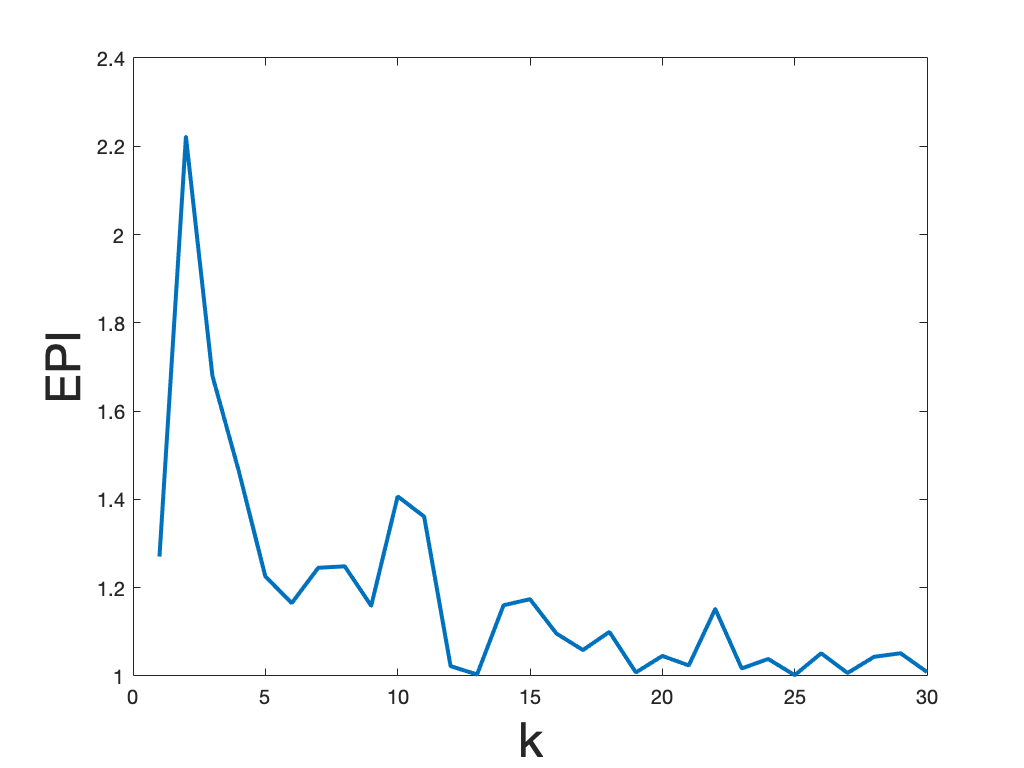

plot(out.ratio(1:30),'linewidth',2.0)
xlabel('k', 'FontSize', 24);
ylabel('EPI', 'FontSize', 24);

## Initial visualization by tSNE

rng(1)
choice_distance = 'cosine';
Dist = squareform(pdist (data,choice_distance));
ydata = tsne_d(Dist);

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.8168
Iteration 20: error is 36.9587
Iteration 30: error is 36.704
Iteration 40: error is 37.516
Iteration 50: error is 36.967
Iteration 60: error is 36.9461
Iteration 70: error is 37.435
Iteration 80: error is 37.5462
Iteration 90: error is 37.6004
Iteration 100: error is 2.3453
Iteration 110: error is 1.2956
Iteration 120: error is 0.93386
Iteration 130: error is 0.79456
Iteration 140: error is 0.6985
Iteration 150: error is 0.66023
Iteration 160: error is 0.65478
Iteration 170: error is 0.65056
Iteration 180: error is 0.64754
Iteration 190: error is 0.64502
Iteration 200: error is 0.64309
Iteration 210: error is 0.64146
Iteration 220: error is 0.64012
Iteration 230: error is 0.639
Iteration 240: error is 0.63808
Iteration 250: error is 0.63723
Iteration 260: error is 0.63593
Iteration 270: error is 0.63452
Iteration 280: error is 0.63337
Iteration 290: error is 0.6325

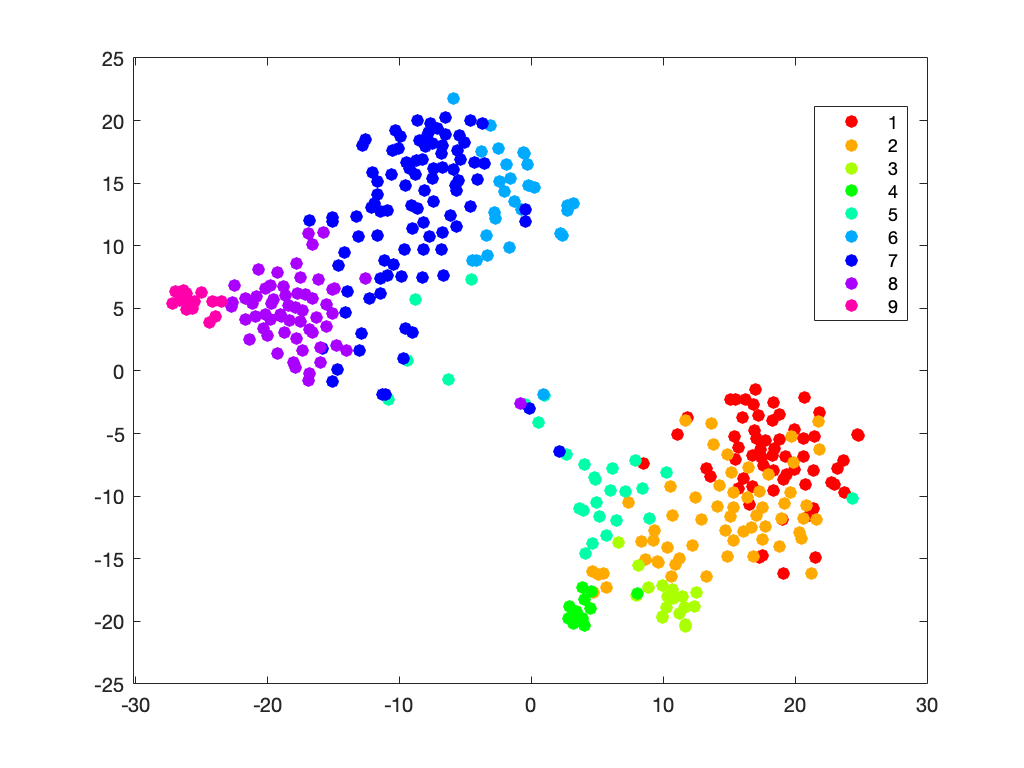

score = ydata;
figure;
gscatter(score(:,1),score(:,2),true_labs,[],[],22);

score_tsne = score;

## MuTrans Dynamical Analysis of the Single-Cell Data

parameter and option settings

rng(1)
par.perplex = 150; 
par.K_cluster = 10;
par.trials = 100;
par.alpha_scale = 0.5;
par.weight_scale = false;
par.true_labs = true_labs;

% Dynamical Analysis and Output
tic;
Output = DynamicalAnalysis (data, par);

Mean value of sigma: 0.35425
Minimum value of sigma: 0.23401
Maximum value of sigma: 0.47158
Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.8168
Iteration 20: error is 36.9587
Iteration 30: error is 36.704
Iteration 40: error is 37.516
Iteration 50: error is 36.967
Iteration 60: error is 36.9461
Iteration 70: error is 37.435
Iteration 80: error is 37.5462
Iteration 90: error is 37.6004
Iteration 100: error is 2.3453
Iteration 110: error is 1.2956
Iteration 120: error is 0.93386
Iteration 130: error is 0.79456
Iteration 140: error is 0.6985
Iteration 150: error is 0.66023
Iteration 160: error is 0.65478
Iteration 170: error is 0.65056
Iteration 180: error is 0.64754
Iteration 190: error is 0.64502
Iteration 200: error is 0.64309
Iteration 210: error is 0.64146
Iteration 220: error is 0.64012
Iteration 230: error is 0.639
Iteration 240: error is 0.63808
Iteration 250: error is 0.63723
Iteration 260: error is 0.63593
I

J_new = 0.8010

J_new = 0.7856

J_new = 0.7618

J_new = 0.7527

J_new = 0.7452

J_new = 0.7447

J_new = 0.7457

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.699
Iteration 20: error is 37.6218
Iteration 30: error is 37.1324
Iteration 40: error is 37.186
Iteration 50: error is 37.4237
Iteration 60: error is 37.6821
Iteration 70: error is 36.8857
Iteration 80: error is 37.5977
Iteration 90: error is 36.9256
Iteration 100: error is 2.2263
Iteration 110: error is 1.2845
Iteration 120: error is 0.91134
Iteration 130: error is 0.75648
Iteration 140: error is 0.70717
Iteration 150: error is 0.67767
Iteration 160: error is 0.66258
Iteration 170: error is 0.65774
Iteration 180: error is 0.65427
Iteration 190: error is 0.65149
Iteration 200: error is 0.64938
Iteration 210: error is 0.64756
Iteration 220: error is 0.64627
Iteration 230: error is 0.64493
Iteration 240: error is 0.64395
Iteration 250: error is 0.64309
Iteration 260: error is 0.64172
Iteration 270: error is 0.64033
Iteration 280: error is 0.63926
Iteration 290: error is 0

J_new = 0.8446

J_new = 0.8322

J_new = 0.8227

J_new = 0.8215

J_new = 0.8224

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.6841
Iteration 20: error is 37.0154
Iteration 30: error is 36.2829
Iteration 40: error is 37.1514
Iteration 50: error is 37.4457
Iteration 60: error is 37.2178
Iteration 70: error is 37.7066
Iteration 80: error is 37.2182
Iteration 90: error is 37.7304
Iteration 100: error is 2.1254
Iteration 110: error is 1.255
Iteration 120: error is 0.808
Iteration 130: error is 0.7124
Iteration 140: error is 0.68225
Iteration 150: error is 0.67087
Iteration 160: error is 0.66272
Iteration 170: error is 0.65805
Iteration 180: error is 0.6544
Iteration 190: error is 0.65163
Iteration 200: error is 0.64937
Iteration 210: error is 0.64784
Iteration 220: error is 0.64606
Iteration 230: error is 0.64483
Iteration 240: error is 0.64376
Iteration 250: error is 0.64286
Iteration 260: error is 0.64143
Iteration 270: error is 0.63993
Iteration 280: error is 0.63875
Iteration 290: error is 0.63

J_new = 0.8090

J_new = 0.7909

J_new = 0.7623

J_new = 0.7525

J_new = 0.7448

J_new = 0.7444

J_new = 0.7453

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.5673
Iteration 20: error is 37.3075
Iteration 30: error is 37.027
Iteration 40: error is 37.3852
Iteration 50: error is 36.7441
Iteration 60: error is 37.3944
Iteration 70: error is 37.558
Iteration 80: error is 36.7687
Iteration 90: error is 37.556
Iteration 100: error is 2.1722
Iteration 110: error is 1.2275
Iteration 120: error is 0.76975
Iteration 130: error is 0.69821
Iteration 140: error is 0.68231
Iteration 150: error is 0.67258
Iteration 160: error is 0.66568
Iteration 170: error is 0.66089
Iteration 180: error is 0.65713
Iteration 190: error is 0.65443
Iteration 200: error is 0.65202
Iteration 210: error is 0.65016
Iteration 220: error is 0.64852
Iteration 230: error is 0.64625
Iteration 240: error is 0.64487
Iteration 250: error is 0.64385
Iteration 260: error is 0.64226
Iteration 270: error is 0.64069
Iteration 280: error is 0.63953
Iteration 290: error is 0.

J_new = 0.8513

J_new = 0.8274

J_new = 0.8155

J_new = 0.8119

J_new = 0.8102

J_new = 0.8057

J_new = 0.8010

J_new = 0.7854

J_new = 0.7435

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.4508
Iteration 20: error is 37.3282
Iteration 30: error is 37.0523
Iteration 40: error is 37.165
Iteration 50: error is 37.0856
Iteration 60: error is 37.4802
Iteration 70: error is 37.5396
Iteration 80: error is 37.5722
Iteration 90: error is 37.7045
Iteration 100: error is 2.3521
Iteration 110: error is 1.3028
Iteration 120: error is 0.95392
Iteration 130: error is 0.83373
Iteration 140: error is 0.6911
Iteration 150: error is 0.66867
Iteration 160: error is 0.66258
Iteration 170: error is 0.65815
Iteration 180: error is 0.65502
Iteration 190: error is 0.65255
Iteration 200: error is 0.65048
Iteration 210: error is 0.64889
Iteration 220: error is 0.64743
Iteration 230: error is 0.64628
Iteration 240: error is 0.64527
Iteration 250: error is 0.64443
Iteration 260: error is 0.64309
Iteration 270: error is 0.64168
Iteration 280: error is 0.6406
Iteration 290: error is 0.

J_new = 0.8441

J_new = 0.8274

J_new = 0.8165

J_new = 0.8145

J_new = 0.8122

J_new = 0.8081

J_new = 0.8065

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.9307
Iteration 20: error is 37.4016
Iteration 30: error is 36.6906
Iteration 40: error is 37.1525
Iteration 50: error is 37.2617
Iteration 60: error is 37.4248
Iteration 70: error is 37.0431
Iteration 80: error is 37.3489
Iteration 90: error is 37.5493
Iteration 100: error is 2.2807
Iteration 110: error is 1.2888
Iteration 120: error is 0.83559
Iteration 130: error is 0.69718
Iteration 140: error is 0.68178
Iteration 150: error is 0.66965
Iteration 160: error is 0.663
Iteration 170: error is 0.65819
Iteration 180: error is 0.65461
Iteration 190: error is 0.65177
Iteration 200: error is 0.64952
Iteration 210: error is 0.64771
Iteration 220: error is 0.64623
Iteration 230: error is 0.64499
Iteration 240: error is 0.64391
Iteration 250: error is 0.64301
Iteration 260: error is 0.64157
Iteration 270: error is 0.64003
Iteration 280: error is 0.63893
Iteration 290: error is 0

J_new = 0.8363

J_new = 0.8202

J_new = 0.8167

J_new = 0.8159

J_new = 0.8136

J_new = 0.8117

J_new = 0.8079

J_new = 0.8061

J_new = 0.8022

J_new = 0.7905

J_new = 0.7811

J_new = 0.7427

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.032
Iteration 20: error is 37.2251
Iteration 30: error is 36.8731
Iteration 40: error is 37.0864
Iteration 50: error is 37.2202
Iteration 60: error is 37.5003
Iteration 70: error is 37.8653
Iteration 80: error is 37.7699
Iteration 90: error is 37.9647
Iteration 100: error is 2.2186
Iteration 110: error is 1.5456
Iteration 120: error is 1.1612
Iteration 130: error is 0.97206
Iteration 140: error is 0.89359
Iteration 150: error is 0.73161
Iteration 160: error is 0.72242
Iteration 170: error is 0.67368
Iteration 180: error is 0.6529
Iteration 190: error is 0.65208
Iteration 200: error is 0.64636
Iteration 210: error is 0.64494
Iteration 220: error is 0.64358
Iteration 230: error is 0.64233
Iteration 240: error is 0.64143
Iteration 250: error is 0.64069
Iteration 260: error is 0.6395
Iteration 270: error is 0.63824
Iteration 280: error is 0.63731
Iteration 290: error is 0.6

J_new = 0.7890

J_new = 0.7614

J_new = 0.7524

J_new = 0.7448

J_new = 0.7444

J_new = 0.7453

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.8452
Iteration 20: error is 36.8708
Iteration 30: error is 37.2209
Iteration 40: error is 37.3125
Iteration 50: error is 37.2101
Iteration 60: error is 37.5151
Iteration 70: error is 36.8521
Iteration 80: error is 37.6564
Iteration 90: error is 37.6055
Iteration 100: error is 2.2291
Iteration 110: error is 1.3095
Iteration 120: error is 1.0519
Iteration 130: error is 0.911
Iteration 140: error is 0.80854
Iteration 150: error is 0.68966
Iteration 160: error is 0.68547
Iteration 170: error is 0.66962
Iteration 180: error is 0.66633
Iteration 190: error is 0.6636
Iteration 200: error is 0.66161
Iteration 210: error is 0.65983
Iteration 220: error is 0.65842
Iteration 230: error is 0.65748
Iteration 240: error is 0.65622
Iteration 250: error is 0.65535
Iteration 260: error is 0.65397
Iteration 270: error is 0.65243
Iteration 280: error is 0.65132
Iteration 290: error is 0.6

J_new = 0.8711

J_new = 0.8422

J_new = 0.8223

J_new = 0.8115

J_new = 0.8090

J_new = 0.8064

J_new = 0.7997

J_new = 0.7860

J_new = 0.7422

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.6785
Iteration 20: error is 36.5532
Iteration 30: error is 36.3915
Iteration 40: error is 36.4791
Iteration 50: error is 36.8499
Iteration 60: error is 36.8137
Iteration 70: error is 36.9157
Iteration 80: error is 36.9918
Iteration 90: error is 37.8186
Iteration 100: error is 2.2581
Iteration 110: error is 1.2752
Iteration 120: error is 0.91516
Iteration 130: error is 0.77904
Iteration 140: error is 0.73195
Iteration 150: error is 0.67895
Iteration 160: error is 0.67064
Iteration 170: error is 0.66638
Iteration 180: error is 0.66318
Iteration 190: error is 0.6607
Iteration 200: error is 0.65867
Iteration 210: error is 0.65701
Iteration 220: error is 0.65567
Iteration 230: error is 0.65451
Iteration 240: error is 0.65353
Iteration 250: error is 0.6527
Iteration 260: error is 0.65136
Iteration 270: error is 0.64998
Iteration 280: error is 0.64883
Iteration 290: error is 0

J_new = 0.8340

J_new = 0.8194

J_new = 0.8158

J_new = 0.8154

J_new = 0.8111

J_new = 0.8092

J_new = 0.8054

J_new = 0.8036

J_new = 0.7898

J_new = 0.7825

J_new = 0.7420

J_new = 0.7429

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.1811
Iteration 20: error is 37.4352
Iteration 30: error is 37.1782
Iteration 40: error is 37.3707
Iteration 50: error is 37.3619
Iteration 60: error is 37.805
Iteration 70: error is 38.2211
Iteration 80: error is 37.9647
Iteration 90: error is 38.6443
Iteration 100: error is 2.4735
Iteration 110: error is 1.4213
Iteration 120: error is 0.86165
Iteration 130: error is 0.79373
Iteration 140: error is 0.69251
Iteration 150: error is 0.68115
Iteration 160: error is 0.67312
Iteration 170: error is 0.66813
Iteration 180: error is 0.66469
Iteration 190: error is 0.66204
Iteration 200: error is 0.65987
Iteration 210: error is 0.65655
Iteration 220: error is 0.64802
Iteration 230: error is 0.64389
Iteration 240: error is 0.64275
Iteration 250: error is 0.6418
Iteration 260: error is 0.64026
Iteration 270: error is 0.63865
Iteration 280: error is 0.63742
Iteration 290: error is 0

J_new = 0.8348

J_new = 0.8193

J_new = 0.8172

J_new = 0.8161

J_new = 0.8139

J_new = 0.8119

J_new = 0.8083

J_new = 0.8064

J_new = 0.8026

J_new = 0.7908

J_new = 0.7815

J_new = 0.7429

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.9152
Iteration 20: error is 37.0837
Iteration 30: error is 36.7335
Iteration 40: error is 36.7648
Iteration 50: error is 36.656
Iteration 60: error is 37.3426
Iteration 70: error is 37.3334
Iteration 80: error is 37.5472
Iteration 90: error is 37.9992
Iteration 100: error is 2.3846
Iteration 110: error is 1.3028
Iteration 120: error is 0.82037
Iteration 130: error is 0.72765
Iteration 140: error is 0.67435
Iteration 150: error is 0.66227
Iteration 160: error is 0.6555
Iteration 170: error is 0.65015
Iteration 180: error is 0.64735
Iteration 190: error is 0.64393
Iteration 200: error is 0.64172
Iteration 210: error is 0.63978
Iteration 220: error is 0.63822
Iteration 230: error is 0.63692
Iteration 240: error is 0.63591
Iteration 250: error is 0.63497
Iteration 260: error is 0.63355
Iteration 270: error is 0.63206
Iteration 280: error is 0.63092
Iteration 290: error is 0

J_new = 0.8061

J_new = 0.7916

J_new = 0.7639

J_new = 0.7484

J_new = 0.7397

J_new = 0.7390

J_new = 0.7401

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.9916
Iteration 20: error is 37.0418
Iteration 30: error is 36.5889
Iteration 40: error is 37.1503
Iteration 50: error is 37.1379
Iteration 60: error is 37.6936
Iteration 70: error is 37.6005
Iteration 80: error is 37.2716
Iteration 90: error is 37.7511
Iteration 100: error is 2.3522
Iteration 110: error is 1.2407
Iteration 120: error is 0.89383
Iteration 130: error is 0.71478
Iteration 140: error is 0.69182
Iteration 150: error is 0.67576
Iteration 160: error is 0.67053
Iteration 170: error is 0.6657
Iteration 180: error is 0.66237
Iteration 190: error is 0.65998
Iteration 200: error is 0.65781
Iteration 210: error is 0.65605
Iteration 220: error is 0.65464
Iteration 230: error is 0.65348
Iteration 240: error is 0.65251
Iteration 250: error is 0.65167
Iteration 260: error is 0.65036
Iteration 270: error is 0.6489
Iteration 280: error is 0.64786
Iteration 290: error is 0

J_new = 0.8346

J_new = 0.8194

J_new = 0.8170

J_new = 0.8163

J_new = 0.8138

J_new = 0.8120

J_new = 0.8081

J_new = 0.8065

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.5491
Iteration 20: error is 36.7223
Iteration 30: error is 36.377
Iteration 40: error is 37.2045
Iteration 50: error is 36.8365
Iteration 60: error is 36.9473
Iteration 70: error is 37.2359
Iteration 80: error is 37.9839
Iteration 90: error is 37.7633
Iteration 100: error is 2.291
Iteration 110: error is 1.2002
Iteration 120: error is 0.77929
Iteration 130: error is 0.74257
Iteration 140: error is 0.69904
Iteration 150: error is 0.68949
Iteration 160: error is 0.68373
Iteration 170: error is 0.67904
Iteration 180: error is 0.67569
Iteration 190: error is 0.67304
Iteration 200: error is 0.671
Iteration 210: error is 0.6651
Iteration 220: error is 0.64505
Iteration 230: error is 0.64111
Iteration 240: error is 0.63982
Iteration 250: error is 0.63882
Iteration 260: error is 0.63717
Iteration 270: error is 0.63542
Iteration 280: error is 0.63418
Iteration 290: error is 0.63

J_new = 0.8330

J_new = 0.8192

J_new = 0.8160

J_new = 0.8132

J_new = 0.8094

J_new = 0.8070

J_new = 0.8002

J_new = 0.7862

J_new = 0.7422

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.468
Iteration 20: error is 36.5733
Iteration 30: error is 36.6275
Iteration 40: error is 36.6309
Iteration 50: error is 37.139
Iteration 60: error is 37.7197
Iteration 70: error is 37.4008
Iteration 80: error is 37.693
Iteration 90: error is 37.6868
Iteration 100: error is 2.3267
Iteration 110: error is 1.2967
Iteration 120: error is 0.88828
Iteration 130: error is 0.7686
Iteration 140: error is 0.73522
Iteration 150: error is 0.68668
Iteration 160: error is 0.67896
Iteration 170: error is 0.66417
Iteration 180: error is 0.65072
Iteration 190: error is 0.64759
Iteration 200: error is 0.64557
Iteration 210: error is 0.64318
Iteration 220: error is 0.64143
Iteration 230: error is 0.64014
Iteration 240: error is 0.63908
Iteration 250: error is 0.63821
Iteration 260: error is 0.63656
Iteration 270: error is 0.63479
Iteration 280: error is 0.63351
Iteration 290: error is 0.6

J_new = 0.8432

J_new = 0.8271

J_new = 0.8168

J_new = 0.8150

J_new = 0.8147

J_new = 0.8110

J_new = 0.8092

J_new = 0.8054

J_new = 0.8036

J_new = 0.7898

J_new = 0.7825

J_new = 0.7420

J_new = 0.7429

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.4716
Iteration 20: error is 37.5475
Iteration 30: error is 37.2252
Iteration 40: error is 37.0895
Iteration 50: error is 37.2813
Iteration 60: error is 37.7198
Iteration 70: error is 37.4096
Iteration 80: error is 37.2074
Iteration 90: error is 37.7908
Iteration 100: error is 2.2654
Iteration 110: error is 1.1701
Iteration 120: error is 0.82575
Iteration 130: error is 0.76367
Iteration 140: error is 0.72734
Iteration 150: error is 0.67227
Iteration 160: error is 0.66384
Iteration 170: error is 0.65861
Iteration 180: error is 0.65543
Iteration 190: error is 0.65286
Iteration 200: error is 0.65102
Iteration 210: error is 0.64924
Iteration 220: error is 0.64785
Iteration 230: error is 0.64672
Iteration 240: error is 0.64571
Iteration 250: error is 0.64487
Iteration 260: error is 0.6436
Iteration 270: error is 0.64224
Iteration 280: error is 0.64118
Iteration 290: error is 

J_new = 0.8702

J_new = 0.8399

J_new = 0.8226

J_new = 0.8120

J_new = 0.8089

J_new = 0.8069

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.2991
Iteration 20: error is 37.1203
Iteration 30: error is 37.1013
Iteration 40: error is 37.1974
Iteration 50: error is 37.2215
Iteration 60: error is 37.4209
Iteration 70: error is 37.7927
Iteration 80: error is 37.5089
Iteration 90: error is 38.1647
Iteration 100: error is 2.2923
Iteration 110: error is 1.1959
Iteration 120: error is 0.83592
Iteration 130: error is 0.69533
Iteration 140: error is 0.67517
Iteration 150: error is 0.66586
Iteration 160: error is 0.65935
Iteration 170: error is 0.65465
Iteration 180: error is 0.65104
Iteration 190: error is 0.64819
Iteration 200: error is 0.64598
Iteration 210: error is 0.64417
Iteration 220: error is 0.64266
Iteration 230: error is 0.64138
Iteration 240: error is 0.64035
Iteration 250: error is 0.63933
Iteration 260: error is 0.63781
Iteration 270: error is 0.63615
Iteration 280: error is 0.63494
Iteration 290: error is

J_new = 0.8436

J_new = 0.8272

J_new = 0.8162

J_new = 0.8142

J_new = 0.8120

J_new = 0.8081

J_new = 0.8065

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.6382
Iteration 20: error is 37.3697
Iteration 30: error is 37.2706
Iteration 40: error is 36.9556
Iteration 50: error is 36.8232
Iteration 60: error is 37.196
Iteration 70: error is 37.5471
Iteration 80: error is 37.6108
Iteration 90: error is 37.8502
Iteration 100: error is 2.1841
Iteration 110: error is 1.3034
Iteration 120: error is 1.048
Iteration 130: error is 0.91348
Iteration 140: error is 0.84397
Iteration 150: error is 0.79837
Iteration 160: error is 0.78127
Iteration 170: error is 0.76307
Iteration 180: error is 0.66936
Iteration 190: error is 0.65151
Iteration 200: error is 0.69172
Iteration 210: error is 0.65002
Iteration 220: error is 0.64209
Iteration 230: error is 0.6379
Iteration 240: error is 0.63711
Iteration 250: error is 0.63642
Iteration 260: error is 0.63532
Iteration 270: error is 0.63409
Iteration 280: error is 0.63322
Iteration 290: error is 0.6

J_new = 0.8436

J_new = 0.8277

J_new = 0.8168

J_new = 0.8146

J_new = 0.8122

J_new = 0.8078

J_new = 0.8063

J_new = 0.8017

J_new = 0.7865

J_new = 0.7423

J_new = 0.7430

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.9742
Iteration 20: error is 37.7682
Iteration 30: error is 36.9064
Iteration 40: error is 37.1332
Iteration 50: error is 37.4659
Iteration 60: error is 36.9861
Iteration 70: error is 37.2404
Iteration 80: error is 37.2745
Iteration 90: error is 36.7446
Iteration 100: error is 2.0949
Iteration 110: error is 1.2554
Iteration 120: error is 0.92465
Iteration 130: error is 0.79797
Iteration 140: error is 0.73271
Iteration 150: error is 0.67021
Iteration 160: error is 0.65857
Iteration 170: error is 0.65287
Iteration 180: error is 0.64944
Iteration 190: error is 0.64682
Iteration 200: error is 0.64429
Iteration 210: error is 0.64251
Iteration 220: error is 0.64107
Iteration 230: error is 0.63983
Iteration 240: error is 0.63877
Iteration 250: error is 0.63789
Iteration 260: error is 0.63647
Iteration 270: error is 0.63495
Iteration 280: error is 0.63377
Iteration 290: error is

J_new = 0.8421

J_new = 0.8272

J_new = 0.8176

J_new = 0.8158

J_new = 0.8149

J_new = 0.8109

J_new = 0.8073

J_new = 0.8025

J_new = 0.7908

J_new = 0.7814

J_new = 0.7432

J_new = 0.7419

J_new = 0.7427

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.242
Iteration 20: error is 36.8829
Iteration 30: error is 36.5191
Iteration 40: error is 36.8548
Iteration 50: error is 37.0783
Iteration 60: error is 36.6617
Iteration 70: error is 37.423
Iteration 80: error is 37.3621
Iteration 90: error is 37.7964
Iteration 100: error is 2.2733
Iteration 110: error is 1.3413
Iteration 120: error is 0.86359
Iteration 130: error is 0.72777
Iteration 140: error is 0.69106
Iteration 150: error is 0.67547
Iteration 160: error is 0.667
Iteration 170: error is 0.66202
Iteration 180: error is 0.65833
Iteration 190: error is 0.65562
Iteration 200: error is 0.65336
Iteration 210: error is 0.65152
Iteration 220: error is 0.65007
Iteration 230: error is 0.64883
Iteration 240: error is 0.64777
Iteration 250: error is 0.64688
Iteration 260: error is 0.64549
Iteration 270: error is 0.64397
Iteration 280: error is 0.64283
Iteration 290: error is 0.6

J_new = 0.8432

J_new = 0.8273

J_new = 0.8156

J_new = 0.8139

J_new = 0.8116

J_new = 0.8079

J_new = 0.8061

J_new = 0.8022

J_new = 0.7905

J_new = 0.7811

J_new = 0.7427

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.0098
Iteration 20: error is 36.9166
Iteration 30: error is 36.2842
Iteration 40: error is 36.6869
Iteration 50: error is 36.8262
Iteration 60: error is 36.4854
Iteration 70: error is 36.9662
Iteration 80: error is 36.964
Iteration 90: error is 37.4471
Iteration 100: error is 2.174
Iteration 110: error is 1.1679
Iteration 120: error is 0.85321
Iteration 130: error is 0.78704
Iteration 140: error is 0.72792
Iteration 150: error is 0.69405
Iteration 160: error is 0.6525
Iteration 170: error is 0.64774
Iteration 180: error is 0.64385
Iteration 190: error is 0.64146
Iteration 200: error is 0.63927
Iteration 210: error is 0.63765
Iteration 220: error is 0.63628
Iteration 230: error is 0.63603
Iteration 240: error is 0.63415
Iteration 250: error is 0.63331
Iteration 260: error is 0.63198
Iteration 270: error is 0.63054
Iteration 280: error is 0.62948
Iteration 290: error is 0.

J_new = 0.7952

J_new = 0.7699

J_new = 0.7534

J_new = 0.7452

J_new = 0.7444

J_new = 0.7453

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.5609
Iteration 20: error is 36.9347
Iteration 30: error is 37.1237
Iteration 40: error is 37.0609
Iteration 50: error is 37.1862
Iteration 60: error is 37.8754
Iteration 70: error is 37.4045
Iteration 80: error is 37.403
Iteration 90: error is 37.5149
Iteration 100: error is 2.0525
Iteration 110: error is 1.1433
Iteration 120: error is 0.84358
Iteration 130: error is 0.70588
Iteration 140: error is 0.67803
Iteration 150: error is 0.6685
Iteration 160: error is 0.66145
Iteration 170: error is 0.65636
Iteration 180: error is 0.65263
Iteration 190: error is 0.64974
Iteration 200: error is 0.64748
Iteration 210: error is 0.64566
Iteration 220: error is 0.64409
Iteration 230: error is 0.64285
Iteration 240: error is 0.64169
Iteration 250: error is 0.64074
Iteration 260: error is 0.63925
Iteration 270: error is 0.63764
Iteration 280: error is 0.63644
Iteration 290: error is 0

J_new = 0.8427

J_new = 0.8270

J_new = 0.8166

J_new = 0.8150

J_new = 0.8145

J_new = 0.8108

J_new = 0.8088

J_new = 0.8052

J_new = 0.8032

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.6269
Iteration 20: error is 37.5425
Iteration 30: error is 37.0587
Iteration 40: error is 36.8077
Iteration 50: error is 37.3071
Iteration 60: error is 37.2803
Iteration 70: error is 37.5208
Iteration 80: error is 37.6743
Iteration 90: error is 38.1767
Iteration 100: error is 2.3163
Iteration 110: error is 1.4627
Iteration 120: error is 0.97588
Iteration 130: error is 0.78315
Iteration 140: error is 0.74273
Iteration 150: error is 0.70787
Iteration 160: error is 0.70223
Iteration 170: error is 0.69793
Iteration 180: error is 0.6951
Iteration 190: error is 0.69293
Iteration 200: error is 0.69093
Iteration 210: error is 0.66445
Iteration 220: error is 0.66187
Iteration 230: error is 0.65914
Iteration 240: error is 0.658
Iteration 250: error is 0.65701
Iteration 260: error is 0.65545
Iteration 270: error is 0.65372
Iteration 280: error is 0.65246
Iteration 290: error is 0.

J_new = 0.8372

J_new = 0.8218

J_new = 0.8199

J_new = 0.8196

J_new = 0.8170

J_new = 0.8168

J_new = 0.8129

J_new = 0.8112

J_new = 0.8073

J_new = 0.8052

J_new = 0.7873

J_new = 0.7453

J_new = 0.7438

J_new = 0.7446

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 40.1877
Iteration 20: error is 37.94
Iteration 30: error is 37.0553
Iteration 40: error is 37.3987
Iteration 50: error is 36.9742
Iteration 60: error is 37.2785
Iteration 70: error is 37.2044
Iteration 80: error is 38.1324
Iteration 90: error is 37.8607
Iteration 100: error is 2.4454
Iteration 110: error is 1.2558
Iteration 120: error is 0.90054
Iteration 130: error is 0.78924
Iteration 140: error is 0.74239
Iteration 150: error is 0.6883
Iteration 160: error is 0.67621
Iteration 170: error is 0.66334
Iteration 180: error is 0.65965
Iteration 190: error is 0.65739
Iteration 200: error is 0.65521
Iteration 210: error is 0.65349
Iteration 220: error is 0.65212
Iteration 230: error is 0.65087
Iteration 240: error is 0.64991
Iteration 250: error is 0.64911
Iteration 260: error is 0.6477
Iteration 270: error is 0.6463
Iteration 280: error is 0.64519
Iteration 290: error is 0.64

J_new = 0.8416

J_new = 0.8264

J_new = 0.8142

J_new = 0.8112

J_new = 0.8098

J_new = 0.8054

J_new = 0.8006

J_new = 0.7851

J_new = 0.7431

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.2662
Iteration 20: error is 36.9309
Iteration 30: error is 36.474
Iteration 40: error is 36.4562
Iteration 50: error is 36.678
Iteration 60: error is 36.9119
Iteration 70: error is 37.3551
Iteration 80: error is 37.3717
Iteration 90: error is 37.6916
Iteration 100: error is 2.3331
Iteration 110: error is 1.421
Iteration 120: error is 0.96839
Iteration 130: error is 0.76504
Iteration 140: error is 0.6722
Iteration 150: error is 0.66768
Iteration 160: error is 0.65886
Iteration 170: error is 0.65442
Iteration 180: error is 0.65143
Iteration 190: error is 0.64927
Iteration 200: error is 0.64704
Iteration 210: error is 0.64549
Iteration 220: error is 0.64417
Iteration 230: error is 0.64299
Iteration 240: error is 0.64205
Iteration 250: error is 0.6412
Iteration 260: error is 0.63991
Iteration 270: error is 0.6384
Iteration 280: error is 0.63737
Iteration 290: error is 0.636

J_new = 0.8400

J_new = 0.8266

J_new = 0.8145

J_new = 0.8116

J_new = 0.8100

J_new = 0.8058

J_new = 0.8009

J_new = 0.7855

J_new = 0.7434

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.9468
Iteration 20: error is 37.4541
Iteration 30: error is 37.301
Iteration 40: error is 37.1213
Iteration 50: error is 37.0785
Iteration 60: error is 37.2981
Iteration 70: error is 37.1567
Iteration 80: error is 37.2489
Iteration 90: error is 37.2374
Iteration 100: error is 2.179
Iteration 110: error is 1.3166
Iteration 120: error is 0.94782
Iteration 130: error is 0.80785
Iteration 140: error is 0.70006
Iteration 150: error is 0.6674
Iteration 160: error is 0.66021
Iteration 170: error is 0.65551
Iteration 180: error is 0.65192
Iteration 190: error is 0.64902
Iteration 200: error is 0.64671
Iteration 210: error is 0.64493
Iteration 220: error is 0.64344
Iteration 230: error is 0.64216
Iteration 240: error is 0.64114
Iteration 250: error is 0.64018
Iteration 260: error is 0.63877
Iteration 270: error is 0.6372
Iteration 280: error is 0.63605
Iteration 290: error is 0.6

J_new = 0.8453

J_new = 0.8276

J_new = 0.8166

J_new = 0.8150

J_new = 0.8145

J_new = 0.8108

J_new = 0.8088

J_new = 0.8052

J_new = 0.8031

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.3836
Iteration 20: error is 36.5764
Iteration 30: error is 36.831
Iteration 40: error is 36.7648
Iteration 50: error is 37.2873
Iteration 60: error is 37.924
Iteration 70: error is 37.6533
Iteration 80: error is 37.4724
Iteration 90: error is 37.0884
Iteration 100: error is 2.3804
Iteration 110: error is 1.2718
Iteration 120: error is 0.85735
Iteration 130: error is 0.73665
Iteration 140: error is 0.71399
Iteration 150: error is 0.70383
Iteration 160: error is 0.69831
Iteration 170: error is 0.69348
Iteration 180: error is 0.69016
Iteration 190: error is 0.68683
Iteration 200: error is 0.65812
Iteration 210: error is 0.64927
Iteration 220: error is 0.64787
Iteration 230: error is 0.64663
Iteration 240: error is 0.64558
Iteration 250: error is 0.6447
Iteration 260: error is 0.64331
Iteration 270: error is 0.64188
Iteration 280: error is 0.6408
Iteration 290: error is 0.6

J_new = 0.7961

J_new = 0.7676

J_new = 0.7508

J_new = 0.7407

J_new = 0.7397

J_new = 0.7401

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.044
Iteration 20: error is 37.2852
Iteration 30: error is 36.9023
Iteration 40: error is 36.9713
Iteration 50: error is 37.3291
Iteration 60: error is 37.3776
Iteration 70: error is 37.3758
Iteration 80: error is 37.0007
Iteration 90: error is 37.5231
Iteration 100: error is 2.2548
Iteration 110: error is 1.1105
Iteration 120: error is 0.77691
Iteration 130: error is 0.70694
Iteration 140: error is 0.68543
Iteration 150: error is 0.67439
Iteration 160: error is 0.6676
Iteration 170: error is 0.66289
Iteration 180: error is 0.6593
Iteration 190: error is 0.65646
Iteration 200: error is 0.65432
Iteration 210: error is 0.65252
Iteration 220: error is 0.65091
Iteration 230: error is 0.64968
Iteration 240: error is 0.64861
Iteration 250: error is 0.6477
Iteration 260: error is 0.64629
Iteration 270: error is 0.64499
Iteration 280: error is 0.64369
Iteration 290: error is 0.6

J_new = 0.8423

J_new = 0.8267

J_new = 0.8148

J_new = 0.8116

J_new = 0.8100

J_new = 0.8058

J_new = 0.8009

J_new = 0.7855

J_new = 0.7434

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.9613
Iteration 20: error is 37.0512
Iteration 30: error is 36.9439
Iteration 40: error is 36.3122
Iteration 50: error is 37.2449
Iteration 60: error is 37.2423
Iteration 70: error is 37.3571
Iteration 80: error is 37.183
Iteration 90: error is 36.6816
Iteration 100: error is 2.3995
Iteration 110: error is 1.4243
Iteration 120: error is 0.91498
Iteration 130: error is 0.83367
Iteration 140: error is 0.79048
Iteration 150: error is 0.72422
Iteration 160: error is 0.67128
Iteration 170: error is 0.65964
Iteration 180: error is 0.65607
Iteration 190: error is 0.6532
Iteration 200: error is 0.65115
Iteration 210: error is 0.64949
Iteration 220: error is 0.64816
Iteration 230: error is 0.64699
Iteration 240: error is 0.64599
Iteration 250: error is 0.64517
Iteration 260: error is 0.64381
Iteration 270: error is 0.64237
Iteration 280: error is 0.64128
Iteration 290: error is 0

J_new = 0.8514

J_new = 0.8279

J_new = 0.8161

J_new = 0.8148

J_new = 0.8143

J_new = 0.8107

J_new = 0.8088

J_new = 0.8052

J_new = 0.8032

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.0769
Iteration 20: error is 36.8821
Iteration 30: error is 36.7211
Iteration 40: error is 37.1192
Iteration 50: error is 36.8081
Iteration 60: error is 37.2307
Iteration 70: error is 36.5909
Iteration 80: error is 37.1964
Iteration 90: error is 37.4676
Iteration 100: error is 2.197
Iteration 110: error is 1.0871
Iteration 120: error is 0.81819
Iteration 130: error is 0.73957
Iteration 140: error is 0.68749
Iteration 150: error is 0.66553
Iteration 160: error is 0.65905
Iteration 170: error is 0.65407
Iteration 180: error is 0.65038
Iteration 190: error is 0.64744
Iteration 200: error is 0.64515
Iteration 210: error is 0.64347
Iteration 220: error is 0.64179
Iteration 230: error is 0.64051
Iteration 240: error is 0.6394
Iteration 250: error is 0.63844
Iteration 260: error is 0.63698
Iteration 270: error is 0.63541
Iteration 280: error is 0.63423
Iteration 290: error is 0

J_new = 0.8416

J_new = 0.8263

J_new = 0.8146

J_new = 0.8116

J_new = 0.8100

J_new = 0.8058

J_new = 0.8009

J_new = 0.7855

J_new = 0.7434

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 40.0457
Iteration 20: error is 37.3998
Iteration 30: error is 37.1825
Iteration 40: error is 37.0605
Iteration 50: error is 37.2708
Iteration 60: error is 37.0419
Iteration 70: error is 37.2445
Iteration 80: error is 37.3601
Iteration 90: error is 37.5471
Iteration 100: error is 2.2614
Iteration 110: error is 1.2836
Iteration 120: error is 0.81852
Iteration 130: error is 0.70513
Iteration 140: error is 0.68181
Iteration 150: error is 0.67123
Iteration 160: error is 0.66447
Iteration 170: error is 0.65933
Iteration 180: error is 0.65571
Iteration 190: error is 0.6535
Iteration 200: error is 0.65065
Iteration 210: error is 0.64884
Iteration 220: error is 0.64736
Iteration 230: error is 0.64612
Iteration 240: error is 0.64508
Iteration 250: error is 0.64415
Iteration 260: error is 0.64271
Iteration 270: error is 0.64115
Iteration 280: error is 0.64001
Iteration 290: error is 

J_new = 0.8693

J_new = 0.8358

J_new = 0.8233

J_new = 0.8142

J_new = 0.8108

J_new = 0.8088

J_new = 0.8052

J_new = 0.8031

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.2299
Iteration 20: error is 37.1384
Iteration 30: error is 36.8842
Iteration 40: error is 36.7533
Iteration 50: error is 37.0079
Iteration 60: error is 36.7442
Iteration 70: error is 36.6901
Iteration 80: error is 36.8998
Iteration 90: error is 37.4389
Iteration 100: error is 2.117
Iteration 110: error is 1.095
Iteration 120: error is 0.8363
Iteration 130: error is 0.7183
Iteration 140: error is 0.68598
Iteration 150: error is 0.67529
Iteration 160: error is 0.66817
Iteration 170: error is 0.66329
Iteration 180: error is 0.65958
Iteration 190: error is 0.65669
Iteration 200: error is 0.65446
Iteration 210: error is 0.65266
Iteration 220: error is 0.65109
Iteration 230: error is 0.64977
Iteration 240: error is 0.64869
Iteration 250: error is 0.64775
Iteration 260: error is 0.6463
Iteration 270: error is 0.64472
Iteration 280: error is 0.64362
Iteration 290: error is 0.64

J_new = 0.8429

J_new = 0.8271

J_new = 0.8166

J_new = 0.8150

J_new = 0.8145

J_new = 0.8108

J_new = 0.8088

J_new = 0.8052

J_new = 0.8031

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 40.3063
Iteration 20: error is 36.6862
Iteration 30: error is 37.0244
Iteration 40: error is 36.9222
Iteration 50: error is 36.9102
Iteration 60: error is 36.9089
Iteration 70: error is 37.1668
Iteration 80: error is 37.636
Iteration 90: error is 37.6127
Iteration 100: error is 2.2423
Iteration 110: error is 1.2087
Iteration 120: error is 0.82911
Iteration 130: error is 0.76046
Iteration 140: error is 0.6816
Iteration 150: error is 0.66893
Iteration 160: error is 0.66129
Iteration 170: error is 0.65635
Iteration 180: error is 0.65247
Iteration 190: error is 0.64973
Iteration 200: error is 0.64751
Iteration 210: error is 0.64565
Iteration 220: error is 0.64416
Iteration 230: error is 0.64307
Iteration 240: error is 0.64194
Iteration 250: error is 0.64103
Iteration 260: error is 0.63964
Iteration 270: error is 0.63816
Iteration 280: error is 0.63707
Iteration 290: error is 0

J_new = 0.8689

J_new = 0.8388

J_new = 0.8218

J_new = 0.8099

J_new = 0.8060

J_new = 0.8011

J_new = 0.7854

J_new = 0.7430

J_new = 0.7416

J_new = 0.7423

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 40.0725
Iteration 20: error is 37.4635
Iteration 30: error is 37.3699
Iteration 40: error is 36.6991
Iteration 50: error is 36.884
Iteration 60: error is 36.9212
Iteration 70: error is 36.905
Iteration 80: error is 37.2185
Iteration 90: error is 37.3731
Iteration 100: error is 2.2393
Iteration 110: error is 1.2014
Iteration 120: error is 0.81819
Iteration 130: error is 0.72749
Iteration 140: error is 0.68419
Iteration 150: error is 0.66698
Iteration 160: error is 0.66062
Iteration 170: error is 0.6557
Iteration 180: error is 0.652
Iteration 190: error is 0.64908
Iteration 200: error is 0.64683
Iteration 210: error is 0.64509
Iteration 220: error is 0.64347
Iteration 230: error is 0.64215
Iteration 240: error is 0.64107
Iteration 250: error is 0.64014
Iteration 260: error is 0.63861
Iteration 270: error is 0.63703
Iteration 280: error is 0.63581
Iteration 290: error is 0.63

J_new = 0.8324

J_new = 0.8189

J_new = 0.8146

J_new = 0.8126

J_new = 0.8094

J_new = 0.8069

J_new = 0.8004

J_new = 0.7865

J_new = 0.7426

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.8127
Iteration 20: error is 36.1601
Iteration 30: error is 36.0184
Iteration 40: error is 36.899
Iteration 50: error is 36.5609
Iteration 60: error is 37.1529
Iteration 70: error is 36.8295
Iteration 80: error is 36.7258
Iteration 90: error is 37.1488
Iteration 100: error is 2.0237
Iteration 110: error is 1.2771
Iteration 120: error is 0.822
Iteration 130: error is 0.74095
Iteration 140: error is 0.68696
Iteration 150: error is 0.67031
Iteration 160: error is 0.664
Iteration 170: error is 0.65942
Iteration 180: error is 0.65578
Iteration 190: error is 0.6531
Iteration 200: error is 0.65091
Iteration 210: error is 0.64919
Iteration 220: error is 0.64773
Iteration 230: error is 0.64652
Iteration 240: error is 0.64559
Iteration 250: error is 0.6446
Iteration 260: error is 0.64323
Iteration 270: error is 0.6418
Iteration 280: error is 0.64075
Iteration 290: error is 0.63999

J_new = 0.8346

J_new = 0.8192

J_new = 0.8171

J_new = 0.8162

J_new = 0.8139

J_new = 0.8119

J_new = 0.8083

J_new = 0.8064

J_new = 0.8026

J_new = 0.7908

J_new = 0.7815

J_new = 0.7429

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.5344
Iteration 20: error is 36.6532
Iteration 30: error is 36.6515
Iteration 40: error is 36.8431
Iteration 50: error is 36.5851
Iteration 60: error is 36.9775
Iteration 70: error is 37.4402
Iteration 80: error is 37.3687
Iteration 90: error is 37.0607
Iteration 100: error is 2.1836
Iteration 110: error is 0.98028
Iteration 120: error is 0.74921
Iteration 130: error is 0.70049
Iteration 140: error is 0.68262
Iteration 150: error is 0.67238
Iteration 160: error is 0.6654
Iteration 170: error is 0.66062
Iteration 180: error is 0.65682
Iteration 190: error is 0.654
Iteration 200: error is 0.65177
Iteration 210: error is 0.64995
Iteration 220: error is 0.64852
Iteration 230: error is 0.64735
Iteration 240: error is 0.64628
Iteration 250: error is 0.6454
Iteration 260: error is 0.6441
Iteration 270: error is 0.64267
Iteration 280: error is 0.64154
Iteration 290: error is 0.6

J_new = 0.8459

J_new = 0.8294

J_new = 0.8188

J_new = 0.8162

J_new = 0.8166

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.1785
Iteration 20: error is 37.0989
Iteration 30: error is 37.0646
Iteration 40: error is 36.9653
Iteration 50: error is 37.0603
Iteration 60: error is 37.5136
Iteration 70: error is 37.5363
Iteration 80: error is 37.5086
Iteration 90: error is 37.8399
Iteration 100: error is 2.1363
Iteration 110: error is 1.1956
Iteration 120: error is 0.78194
Iteration 130: error is 0.71672
Iteration 140: error is 0.68139
Iteration 150: error is 0.66988
Iteration 160: error is 0.66422
Iteration 170: error is 0.65947
Iteration 180: error is 0.65618
Iteration 190: error is 0.65337
Iteration 200: error is 0.65122
Iteration 210: error is 0.64944
Iteration 220: error is 0.64791
Iteration 230: error is 0.64645
Iteration 240: error is 0.64364
Iteration 250: error is 0.64274
Iteration 260: error is 0.6413
Iteration 270: error is 0.63974
Iteration 280: error is 0.63864
Iteration 290: error is 

J_new = 0.8486

J_new = 0.8265

J_new = 0.8147

J_new = 0.8115

J_new = 0.8101

J_new = 0.8057

J_new = 0.8010

J_new = 0.7854

J_new = 0.7435

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.671
Iteration 20: error is 36.9636
Iteration 30: error is 36.454
Iteration 40: error is 36.8364
Iteration 50: error is 37.1997
Iteration 60: error is 37.2005
Iteration 70: error is 37.2284
Iteration 80: error is 37.005
Iteration 90: error is 37.0916
Iteration 100: error is 2.2722
Iteration 110: error is 1.2857
Iteration 120: error is 0.96325
Iteration 130: error is 0.80245
Iteration 140: error is 0.73453
Iteration 150: error is 0.70946
Iteration 160: error is 0.69853
Iteration 170: error is 0.69437
Iteration 180: error is 0.69104
Iteration 190: error is 0.68853
Iteration 200: error is 0.68666
Iteration 210: error is 0.68508
Iteration 220: error is 0.68369
Iteration 230: error is 0.68259
Iteration 240: error is 0.68152
Iteration 250: error is 0.68071
Iteration 260: error is 0.67948
Iteration 270: error is 0.67823
Iteration 280: error is 0.67724
Iteration 290: error is 0.

J_new = 0.8468

J_new = 0.8329

J_new = 0.8238

J_new = 0.8217

J_new = 0.8228

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.6529
Iteration 20: error is 36.8493
Iteration 30: error is 36.9484
Iteration 40: error is 37.6785
Iteration 50: error is 37.3785
Iteration 60: error is 37.184
Iteration 70: error is 37.5954
Iteration 80: error is 37.4321
Iteration 90: error is 37.7045
Iteration 100: error is 2.3193
Iteration 110: error is 1.1669
Iteration 120: error is 0.86169
Iteration 130: error is 0.72219
Iteration 140: error is 0.72025
Iteration 150: error is 0.68362
Iteration 160: error is 0.66154
Iteration 170: error is 0.6569
Iteration 180: error is 0.65361
Iteration 190: error is 0.65036
Iteration 200: error is 0.64805
Iteration 210: error is 0.64631
Iteration 220: error is 0.64483
Iteration 230: error is 0.64363
Iteration 240: error is 0.64268
Iteration 250: error is 0.64166
Iteration 260: error is 0.64023
Iteration 270: error is 0.63875
Iteration 280: error is 0.63757
Iteration 290: error is 0

J_new = 0.8091

J_new = 0.7974

J_new = 0.7740

J_new = 0.7542

J_new = 0.7457

J_new = 0.7393

J_new = 0.7386

J_new = 0.7396

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.7344
Iteration 20: error is 37.0594
Iteration 30: error is 36.785
Iteration 40: error is 36.7658
Iteration 50: error is 37.298
Iteration 60: error is 37.361
Iteration 70: error is 37.3699
Iteration 80: error is 37.5414
Iteration 90: error is 37.3151
Iteration 100: error is 2.2833
Iteration 110: error is 1.1606
Iteration 120: error is 0.83473
Iteration 130: error is 0.71549
Iteration 140: error is 0.69997
Iteration 150: error is 0.67847
Iteration 160: error is 0.67277
Iteration 170: error is 0.66849
Iteration 180: error is 0.66525
Iteration 190: error is 0.66267
Iteration 200: error is 0.66076
Iteration 210: error is 0.65906
Iteration 220: error is 0.65772
Iteration 230: error is 0.65659
Iteration 240: error is 0.65557
Iteration 250: error is 0.6547
Iteration 260: error is 0.65337
Iteration 270: error is 0.65185
Iteration 280: error is 0.65083
Iteration 290: error is 0.6

J_new = 0.8372

J_new = 0.8192

J_new = 0.8171

J_new = 0.8161

J_new = 0.8139

J_new = 0.8119

J_new = 0.8083

J_new = 0.8064

J_new = 0.8026

J_new = 0.7908

J_new = 0.7815

J_new = 0.7429

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 40.099
Iteration 20: error is 38.1897
Iteration 30: error is 37.1084
Iteration 40: error is 36.9637
Iteration 50: error is 37.5701
Iteration 60: error is 37.3491
Iteration 70: error is 36.7932
Iteration 80: error is 37.4949
Iteration 90: error is 37.5706
Iteration 100: error is 2.2601
Iteration 110: error is 1.1809
Iteration 120: error is 0.79624
Iteration 130: error is 0.69692
Iteration 140: error is 0.68058
Iteration 150: error is 0.67116
Iteration 160: error is 0.66443
Iteration 170: error is 0.65965
Iteration 180: error is 0.65607
Iteration 190: error is 0.65332
Iteration 200: error is 0.65116
Iteration 210: error is 0.64937
Iteration 220: error is 0.64793
Iteration 230: error is 0.64677
Iteration 240: error is 0.64568
Iteration 250: error is 0.64475
Iteration 260: error is 0.64335
Iteration 270: error is 0.64186
Iteration 280: error is 0.64079
Iteration 290: error is 

J_new = 0.8898

J_new = 0.8738

J_new = 0.8500

J_new = 0.8326

J_new = 0.8245

J_new = 0.8240

J_new = 0.8239

J_new = 0.8226

J_new = 0.8234

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.4051
Iteration 20: error is 37.2066
Iteration 30: error is 36.7215
Iteration 40: error is 37.2066
Iteration 50: error is 37.7491
Iteration 60: error is 38.0151
Iteration 70: error is 37.5547
Iteration 80: error is 37.7486
Iteration 90: error is 37.75
Iteration 100: error is 2.4012
Iteration 110: error is 1.4425
Iteration 120: error is 0.99148
Iteration 130: error is 0.84039
Iteration 140: error is 0.77529
Iteration 150: error is 0.73863
Iteration 160: error is 0.67425
Iteration 170: error is 0.66346
Iteration 180: error is 0.65892
Iteration 190: error is 0.65591
Iteration 200: error is 0.65366
Iteration 210: error is 0.65185
Iteration 220: error is 0.65043
Iteration 230: error is 0.64914
Iteration 240: error is 0.64818
Iteration 250: error is 0.64722
Iteration 260: error is 0.64583
Iteration 270: error is 0.6443
Iteration 280: error is 0.64321
Iteration 290: error is 0.

J_new = 0.8431

J_new = 0.8276

J_new = 0.8180

J_new = 0.8160

J_new = 0.8158

J_new = 0.8134

J_new = 0.8117

J_new = 0.8079

J_new = 0.8061

J_new = 0.8022

J_new = 0.7905

J_new = 0.7811

J_new = 0.7427

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.0418
Iteration 20: error is 37.1782
Iteration 30: error is 36.8972
Iteration 40: error is 37.4132
Iteration 50: error is 37.0167
Iteration 60: error is 37.1655
Iteration 70: error is 37.243
Iteration 80: error is 37.77
Iteration 90: error is 37.6078
Iteration 100: error is 2.2541
Iteration 110: error is 1.4263
Iteration 120: error is 0.92412
Iteration 130: error is 0.77345
Iteration 140: error is 0.72946
Iteration 150: error is 0.70332
Iteration 160: error is 0.68085
Iteration 170: error is 0.67157
Iteration 180: error is 0.66806
Iteration 190: error is 0.66523
Iteration 200: error is 0.66312
Iteration 210: error is 0.6613
Iteration 220: error is 0.65991
Iteration 230: error is 0.6586
Iteration 240: error is 0.65757
Iteration 250: error is 0.65669
Iteration 260: error is 0.65523
Iteration 270: error is 0.6537
Iteration 280: error is 0.65256
Iteration 290: error is 0.651

J_new = 0.8331

J_new = 0.8174

J_new = 0.8140

J_new = 0.8122

J_new = 0.8088

J_new = 0.8064

J_new = 0.7997

J_new = 0.7860

J_new = 0.7422

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.9118
Iteration 20: error is 36.9312
Iteration 30: error is 37.2443
Iteration 40: error is 37.1057
Iteration 50: error is 37.148
Iteration 60: error is 37.0857
Iteration 70: error is 37.5898
Iteration 80: error is 37.4517
Iteration 90: error is 37.5601
Iteration 100: error is 2.1456
Iteration 110: error is 1.3633
Iteration 120: error is 0.89527
Iteration 130: error is 0.76854
Iteration 140: error is 0.72765
Iteration 150: error is 0.67636
Iteration 160: error is 0.66633
Iteration 170: error is 0.66168
Iteration 180: error is 0.65837
Iteration 190: error is 0.65587
Iteration 200: error is 0.65382
Iteration 210: error is 0.65211
Iteration 220: error is 0.65073
Iteration 230: error is 0.64959
Iteration 240: error is 0.64865
Iteration 250: error is 0.64783
Iteration 260: error is 0.64655
Iteration 270: error is 0.6452
Iteration 280: error is 0.6442
Iteration 290: error is 0.

J_new = 0.8431

J_new = 0.8272

J_new = 0.8170

J_new = 0.8154

J_new = 0.8148

J_new = 0.8112

J_new = 0.8090

J_new = 0.8056

J_new = 0.8034

J_new = 0.7900

J_new = 0.7823

J_new = 0.7422

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.8651
Iteration 20: error is 37.0572
Iteration 30: error is 36.9058
Iteration 40: error is 36.739
Iteration 50: error is 36.8609
Iteration 60: error is 36.9843
Iteration 70: error is 36.4582
Iteration 80: error is 36.617
Iteration 90: error is 36.6478
Iteration 100: error is 2.2117
Iteration 110: error is 1.2289
Iteration 120: error is 0.77205
Iteration 130: error is 0.72284
Iteration 140: error is 0.70596
Iteration 150: error is 0.68494
Iteration 160: error is 0.67009
Iteration 170: error is 0.66434
Iteration 180: error is 0.66011
Iteration 190: error is 0.6571
Iteration 200: error is 0.65431
Iteration 210: error is 0.65234
Iteration 220: error is 0.65063
Iteration 230: error is 0.64928
Iteration 240: error is 0.64812
Iteration 250: error is 0.64713
Iteration 260: error is 0.64568
Iteration 270: error is 0.6439
Iteration 280: error is 0.64276
Iteration 290: error is 0.6

J_new = 0.8540

J_new = 0.8286

J_new = 0.8184

J_new = 0.8164

J_new = 0.8160

J_new = 0.8138

J_new = 0.8119

J_new = 0.8083

J_new = 0.8064

J_new = 0.8026

J_new = 0.7908

J_new = 0.7815

J_new = 0.7429

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.5709
Iteration 20: error is 36.8363
Iteration 30: error is 36.8701
Iteration 40: error is 37.0065
Iteration 50: error is 37.5598
Iteration 60: error is 37.1529
Iteration 70: error is 37.3826
Iteration 80: error is 37.5491
Iteration 90: error is 37.1911
Iteration 100: error is 2.1331
Iteration 110: error is 1.2846
Iteration 120: error is 0.87898
Iteration 130: error is 0.7194
Iteration 140: error is 0.68153
Iteration 150: error is 0.66611
Iteration 160: error is 0.65935
Iteration 170: error is 0.65414
Iteration 180: error is 0.65006
Iteration 190: error is 0.64687
Iteration 200: error is 0.64458
Iteration 210: error is 0.64265
Iteration 220: error is 0.64103
Iteration 230: error is 0.63966
Iteration 240: error is 0.63856
Iteration 250: error is 0.63769
Iteration 260: error is 0.63626
Iteration 270: error is 0.63476
Iteration 280: error is 0.63368
Iteration 290: error is 

J_new = 0.8079

J_new = 0.7957

J_new = 0.7773

J_new = 0.7616

J_new = 0.7529

J_new = 0.7450

J_new = 0.7449

J_new = 0.7456

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.9924
Iteration 20: error is 37.3447
Iteration 30: error is 36.7011
Iteration 40: error is 36.922
Iteration 50: error is 37.5165
Iteration 60: error is 37.3932
Iteration 70: error is 37.4356
Iteration 80: error is 37.8052
Iteration 90: error is 38.1366
Iteration 100: error is 2.2795
Iteration 110: error is 1.3452
Iteration 120: error is 0.89213
Iteration 130: error is 0.78958
Iteration 140: error is 0.71249
Iteration 150: error is 0.66963
Iteration 160: error is 0.6633
Iteration 170: error is 0.6589
Iteration 180: error is 0.6557
Iteration 190: error is 0.65315
Iteration 200: error is 0.65104
Iteration 210: error is 0.64933
Iteration 220: error is 0.64794
Iteration 230: error is 0.64678
Iteration 240: error is 0.64577
Iteration 250: error is 0.64501
Iteration 260: error is 0.64358
Iteration 270: error is 0.64214
Iteration 280: error is 0.64109
Iteration 290: error is 0.6

J_new = 0.8317

J_new = 0.8183

J_new = 0.8142

J_new = 0.8124

J_new = 0.8090

J_new = 0.8067

J_new = 0.7999

J_new = 0.7862

J_new = 0.7422

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.3667
Iteration 20: error is 37.3814
Iteration 30: error is 37.2769
Iteration 40: error is 37.1683
Iteration 50: error is 37.5463
Iteration 60: error is 37.7897
Iteration 70: error is 38.3422
Iteration 80: error is 38.2968
Iteration 90: error is 37.9269
Iteration 100: error is 2.4464
Iteration 110: error is 1.4068
Iteration 120: error is 0.99317
Iteration 130: error is 0.84336
Iteration 140: error is 0.76466
Iteration 150: error is 0.68677
Iteration 160: error is 0.65943
Iteration 170: error is 0.65528
Iteration 180: error is 0.65237
Iteration 190: error is 0.65008
Iteration 200: error is 0.64824
Iteration 210: error is 0.64668
Iteration 220: error is 0.64533
Iteration 230: error is 0.64416
Iteration 240: error is 0.64328
Iteration 250: error is 0.64249
Iteration 260: error is 0.64122
Iteration 270: error is 0.63986
Iteration 280: error is 0.63885
Iteration 290: error is

J_new = 0.8445

J_new = 0.8288

J_new = 0.8180

J_new = 0.8162

J_new = 0.8159

J_new = 0.8135

J_new = 0.8116

J_new = 0.8079

J_new = 0.8061

J_new = 0.8022

J_new = 0.7905

J_new = 0.7811

J_new = 0.7427

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 40.3972
Iteration 20: error is 37.1465
Iteration 30: error is 36.9894
Iteration 40: error is 37.5889
Iteration 50: error is 37.4417
Iteration 60: error is 37.6505
Iteration 70: error is 37.0782
Iteration 80: error is 37.1591
Iteration 90: error is 37.7285
Iteration 100: error is 2.2748
Iteration 110: error is 1.2969
Iteration 120: error is 0.90917
Iteration 130: error is 0.81615
Iteration 140: error is 0.75766
Iteration 150: error is 0.69252
Iteration 160: error is 0.66306
Iteration 170: error is 0.65649
Iteration 180: error is 0.65297
Iteration 190: error is 0.6502
Iteration 200: error is 0.64755
Iteration 210: error is 0.64565
Iteration 220: error is 0.64413
Iteration 230: error is 0.64288
Iteration 240: error is 0.64178
Iteration 250: error is 0.64089
Iteration 260: error is 0.63939
Iteration 270: error is 0.63778
Iteration 280: error is 0.63662
Iteration 290: error is 

J_new = 0.8345

J_new = 0.8190

J_new = 0.8162

J_new = 0.8152

J_new = 0.8109

J_new = 0.8088

J_new = 0.8052

J_new = 0.8031

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.6872
Iteration 20: error is 37.1874
Iteration 30: error is 37.2847
Iteration 40: error is 36.592
Iteration 50: error is 37.0542
Iteration 60: error is 37.4377
Iteration 70: error is 37.7104
Iteration 80: error is 37.4039
Iteration 90: error is 37.2774
Iteration 100: error is 2.2873
Iteration 110: error is 1.026
Iteration 120: error is 0.74959
Iteration 130: error is 0.70014
Iteration 140: error is 0.68382
Iteration 150: error is 0.67353
Iteration 160: error is 0.66687
Iteration 170: error is 0.66187
Iteration 180: error is 0.65812
Iteration 190: error is 0.65513
Iteration 200: error is 0.65282
Iteration 210: error is 0.65088
Iteration 220: error is 0.64932
Iteration 230: error is 0.64803
Iteration 240: error is 0.64691
Iteration 250: error is 0.64592
Iteration 260: error is 0.6444
Iteration 270: error is 0.64274
Iteration 280: error is 0.64154
Iteration 290: error is 0.

J_new = 0.8440

J_new = 0.8287

J_new = 0.8182

J_new = 0.8165

J_new = 0.8162

J_new = 0.8137

J_new = 0.8120

J_new = 0.8081

J_new = 0.8065

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.6676
Iteration 20: error is 37.3248
Iteration 30: error is 36.9647
Iteration 40: error is 36.8349
Iteration 50: error is 36.725
Iteration 60: error is 36.8717
Iteration 70: error is 37.0522
Iteration 80: error is 37.5126
Iteration 90: error is 37.1538
Iteration 100: error is 2.3035
Iteration 110: error is 1.273
Iteration 120: error is 0.90283
Iteration 130: error is 0.79848
Iteration 140: error is 0.74969
Iteration 150: error is 0.68612
Iteration 160: error is 0.66346
Iteration 170: error is 0.6591
Iteration 180: error is 0.65585
Iteration 190: error is 0.65337
Iteration 200: error is 0.65125
Iteration 210: error is 0.64953
Iteration 220: error is 0.64811
Iteration 230: error is 0.64696
Iteration 240: error is 0.64587
Iteration 250: error is 0.64509
Iteration 260: error is 0.64365
Iteration 270: error is 0.64223
Iteration 280: error is 0.6411
Iteration 290: error is 0.6

J_new = 0.8365

J_new = 0.8187

J_new = 0.8155

J_new = 0.8149

J_new = 0.8108

J_new = 0.8088

J_new = 0.8052

J_new = 0.8032

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.8495
Iteration 20: error is 36.574
Iteration 30: error is 36.9197
Iteration 40: error is 37.0171
Iteration 50: error is 37.0223
Iteration 60: error is 37.5533
Iteration 70: error is 37.6533
Iteration 80: error is 36.9301
Iteration 90: error is 37.3047
Iteration 100: error is 2.1108
Iteration 110: error is 1.1562
Iteration 120: error is 0.88948
Iteration 130: error is 0.84051
Iteration 140: error is 0.78537
Iteration 150: error is 0.69117
Iteration 160: error is 0.66519
Iteration 170: error is 0.65828
Iteration 180: error is 0.65455
Iteration 190: error is 0.65158
Iteration 200: error is 0.64963
Iteration 210: error is 0.64803
Iteration 220: error is 0.64672
Iteration 230: error is 0.6456
Iteration 240: error is 0.64487
Iteration 250: error is 0.64386
Iteration 260: error is 0.64309
Iteration 270: error is 0.63955
Iteration 280: error is 0.63826
Iteration 290: error is 0

J_new = 0.8368

J_new = 0.8190

J_new = 0.8159

J_new = 0.8154

J_new = 0.8111

J_new = 0.8092

J_new = 0.8054

J_new = 0.8036

J_new = 0.7898

J_new = 0.7825

J_new = 0.7420

J_new = 0.7429

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.3008
Iteration 20: error is 36.7463
Iteration 30: error is 36.9066
Iteration 40: error is 37.1682
Iteration 50: error is 37.344
Iteration 60: error is 37.6389
Iteration 70: error is 38.4718
Iteration 80: error is 37.3005
Iteration 90: error is 37.1258
Iteration 100: error is 2.2392
Iteration 110: error is 1.2075
Iteration 120: error is 0.91064
Iteration 130: error is 0.85397
Iteration 140: error is 0.82257
Iteration 150: error is 0.70778
Iteration 160: error is 0.6997
Iteration 170: error is 0.69343
Iteration 180: error is 0.69017
Iteration 190: error is 0.68753
Iteration 200: error is 0.68543
Iteration 210: error is 0.68356
Iteration 220: error is 0.68223
Iteration 230: error is 0.68124
Iteration 240: error is 0.68025
Iteration 250: error is 0.67938
Iteration 260: error is 0.67813
Iteration 270: error is 0.67678
Iteration 280: error is 0.67582
Iteration 290: error is 0

J_new = 0.8539

J_new = 0.8209

J_new = 0.8095

J_new = 0.8062

J_new = 0.8011

J_new = 0.7853

J_new = 0.7431

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.9095
Iteration 20: error is 37.3471
Iteration 30: error is 36.7427
Iteration 40: error is 36.4494
Iteration 50: error is 36.7278
Iteration 60: error is 37.2611
Iteration 70: error is 37.1789
Iteration 80: error is 37.9062
Iteration 90: error is 37.4844
Iteration 100: error is 2.1484
Iteration 110: error is 1.0857
Iteration 120: error is 0.77835
Iteration 130: error is 0.70163
Iteration 140: error is 0.68192
Iteration 150: error is 0.67178
Iteration 160: error is 0.66484
Iteration 170: error is 0.65996
Iteration 180: error is 0.65631
Iteration 190: error is 0.65348
Iteration 200: error is 0.65127
Iteration 210: error is 0.64943
Iteration 220: error is 0.64793
Iteration 230: error is 0.6467
Iteration 240: error is 0.64553
Iteration 250: error is 0.64469
Iteration 260: error is 0.64327
Iteration 270: error is 0.64181
Iteration 280: error is 0.6407
Iteration 290: error is 0

J_new = 0.8521

J_new = 0.8279

J_new = 0.8175

J_new = 0.8163

J_new = 0.8157

J_new = 0.8139

J_new = 0.8118

J_new = 0.8064

J_new = 0.8035

J_new = 0.7899

J_new = 0.7824

J_new = 0.7422

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.1836
Iteration 20: error is 36.7143
Iteration 30: error is 36.7616
Iteration 40: error is 37.3901
Iteration 50: error is 36.5329
Iteration 60: error is 37.5878
Iteration 70: error is 37.5452
Iteration 80: error is 37.4385
Iteration 90: error is 38.0082
Iteration 100: error is 2.2245
Iteration 110: error is 1.2215
Iteration 120: error is 0.87111
Iteration 130: error is 0.77832
Iteration 140: error is 0.68966
Iteration 150: error is 0.67407
Iteration 160: error is 0.66791
Iteration 170: error is 0.66325
Iteration 180: error is 0.65906
Iteration 190: error is 0.65628
Iteration 200: error is 0.6542
Iteration 210: error is 0.65254
Iteration 220: error is 0.65109
Iteration 230: error is 0.64995
Iteration 240: error is 0.64895
Iteration 250: error is 0.64807
Iteration 260: error is 0.64673
Iteration 270: error is 0.64525
Iteration 280: error is 0.64415
Iteration 290: error is 

J_new = 0.8084

J_new = 0.7939

J_new = 0.7703

J_new = 0.7534

J_new = 0.7452

J_new = 0.7444

J_new = 0.7453

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.1149
Iteration 20: error is 36.5796
Iteration 30: error is 36.9025
Iteration 40: error is 36.9507
Iteration 50: error is 36.9921
Iteration 60: error is 37.7863
Iteration 70: error is 37.7552
Iteration 80: error is 37.2033
Iteration 90: error is 37.3691
Iteration 100: error is 2.2768
Iteration 110: error is 1.2973
Iteration 120: error is 0.93066
Iteration 130: error is 0.84567
Iteration 140: error is 0.82242
Iteration 150: error is 0.80539
Iteration 160: error is 0.78345
Iteration 170: error is 0.75476
Iteration 180: error is 0.75284
Iteration 190: error is 0.66834
Iteration 200: error is 0.66121
Iteration 210: error is 0.65748
Iteration 220: error is 0.65603
Iteration 230: error is 0.65481
Iteration 240: error is 0.65302
Iteration 250: error is 0.65186
Iteration 260: error is 0.65034
Iteration 270: error is 0.64854
Iteration 280: error is 0.64746
Iteration 290: error is

J_new = 0.8569

J_new = 0.8276

J_new = 0.8156

J_new = 0.8139

J_new = 0.8117

J_new = 0.8079

J_new = 0.8061

J_new = 0.8022

J_new = 0.7905

J_new = 0.7811

J_new = 0.7427

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.1255
Iteration 20: error is 36.8754
Iteration 30: error is 36.9111
Iteration 40: error is 36.7055
Iteration 50: error is 37.4355
Iteration 60: error is 36.9182
Iteration 70: error is 37.5657
Iteration 80: error is 37.2436
Iteration 90: error is 37.6263
Iteration 100: error is 2.2173
Iteration 110: error is 1.3342
Iteration 120: error is 1.0861
Iteration 130: error is 0.91113
Iteration 140: error is 0.81986
Iteration 150: error is 0.71278
Iteration 160: error is 0.69181
Iteration 170: error is 0.65931
Iteration 180: error is 0.65604
Iteration 190: error is 0.65396
Iteration 200: error is 0.65214
Iteration 210: error is 0.65068
Iteration 220: error is 0.64953
Iteration 230: error is 0.6483
Iteration 240: error is 0.64738
Iteration 250: error is 0.6466
Iteration 260: error is 0.64536
Iteration 270: error is 0.64395
Iteration 280: error is 0.64292
Iteration 290: error is 0.

J_new = 0.8702

J_new = 0.8384

J_new = 0.8213

J_new = 0.8097

J_new = 0.8063

J_new = 0.8014

J_new = 0.7857

J_new = 0.7434

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.7858
Iteration 20: error is 37.0692
Iteration 30: error is 37.3712
Iteration 40: error is 36.7248
Iteration 50: error is 36.997
Iteration 60: error is 37.1212
Iteration 70: error is 37.7949
Iteration 80: error is 37.3347
Iteration 90: error is 37.4757
Iteration 100: error is 2.3065
Iteration 110: error is 1.2269
Iteration 120: error is 0.80337
Iteration 130: error is 0.74298
Iteration 140: error is 0.70122
Iteration 150: error is 0.68572
Iteration 160: error is 0.67922
Iteration 170: error is 0.67439
Iteration 180: error is 0.67079
Iteration 190: error is 0.66806
Iteration 200: error is 0.66585
Iteration 210: error is 0.66402
Iteration 220: error is 0.66254
Iteration 230: error is 0.66128
Iteration 240: error is 0.66026
Iteration 250: error is 0.65936
Iteration 260: error is 0.65794
Iteration 270: error is 0.65639
Iteration 280: error is 0.65525
Iteration 290: error is 

J_new = 0.7846

J_new = 0.7625

J_new = 0.7502

J_new = 0.7402

J_new = 0.7398

J_new = 0.7399

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.7935
Iteration 20: error is 37.4008
Iteration 30: error is 36.8741
Iteration 40: error is 37.4626
Iteration 50: error is 37.2276
Iteration 60: error is 36.7086
Iteration 70: error is 37.9142
Iteration 80: error is 37.4265
Iteration 90: error is 37.4402
Iteration 100: error is 2.1693
Iteration 110: error is 1.3047
Iteration 120: error is 0.89216
Iteration 130: error is 0.82463
Iteration 140: error is 0.76015
Iteration 150: error is 0.71563
Iteration 160: error is 0.6762
Iteration 170: error is 0.67099
Iteration 180: error is 0.66518
Iteration 190: error is 0.66226
Iteration 200: error is 0.65986
Iteration 210: error is 0.65775
Iteration 220: error is 0.65613
Iteration 230: error is 0.65484
Iteration 240: error is 0.65382
Iteration 250: error is 0.65298
Iteration 260: error is 0.6516
Iteration 270: error is 0.65007
Iteration 280: error is 0.64899
Iteration 290: error is 0

J_new = 0.8379

J_new = 0.8221

J_new = 0.8148

J_new = 0.8116

J_new = 0.8099

J_new = 0.8054

J_new = 0.8006

J_new = 0.7851

J_new = 0.7431

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.6753
Iteration 20: error is 37.8451
Iteration 30: error is 37.163
Iteration 40: error is 37.615
Iteration 50: error is 37.9545
Iteration 60: error is 37.4721
Iteration 70: error is 37.3621
Iteration 80: error is 37.7004
Iteration 90: error is 37.5517
Iteration 100: error is 2.2443
Iteration 110: error is 1.1409
Iteration 120: error is 0.76407
Iteration 130: error is 0.69906
Iteration 140: error is 0.67741
Iteration 150: error is 0.66692
Iteration 160: error is 0.65979
Iteration 170: error is 0.65471
Iteration 180: error is 0.65074
Iteration 190: error is 0.64774
Iteration 200: error is 0.64534
Iteration 210: error is 0.64338
Iteration 220: error is 0.64178
Iteration 230: error is 0.6404
Iteration 240: error is 0.63923
Iteration 250: error is 0.63823
Iteration 260: error is 0.6367
Iteration 270: error is 0.63508
Iteration 280: error is 0.63387
Iteration 290: error is 0.6

J_new = 0.8430

J_new = 0.8274

J_new = 0.8175

J_new = 0.8156

J_new = 0.8148

J_new = 0.8111

J_new = 0.8072

J_new = 0.8027

J_new = 0.7907

J_new = 0.7816

J_new = 0.7430

J_new = 0.7421

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.5278
Iteration 20: error is 37.3151
Iteration 30: error is 36.7133
Iteration 40: error is 37.1292
Iteration 50: error is 37.4111
Iteration 60: error is 37.475
Iteration 70: error is 36.4882
Iteration 80: error is 37.2606
Iteration 90: error is 37.743
Iteration 100: error is 2.3511
Iteration 110: error is 1.2702
Iteration 120: error is 0.88865
Iteration 130: error is 0.83442
Iteration 140: error is 0.8077
Iteration 150: error is 0.787
Iteration 160: error is 0.74196
Iteration 170: error is 0.66441
Iteration 180: error is 0.65943
Iteration 190: error is 0.6572
Iteration 200: error is 0.6554
Iteration 210: error is 0.65384
Iteration 220: error is 0.65262
Iteration 230: error is 0.65154
Iteration 240: error is 0.65057
Iteration 250: error is 0.64811
Iteration 260: error is 0.64679
Iteration 270: error is 0.64545
Iteration 280: error is 0.64443
Iteration 290: error is 0.6436

J_new = 0.8029

J_new = 0.7870

J_new = 0.7627

J_new = 0.7533

J_new = 0.7451

J_new = 0.7449

J_new = 0.7456

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.6267
Iteration 20: error is 36.9948
Iteration 30: error is 36.7511
Iteration 40: error is 36.4511
Iteration 50: error is 36.7186
Iteration 60: error is 37.2168
Iteration 70: error is 36.8085
Iteration 80: error is 37.0277
Iteration 90: error is 36.8353
Iteration 100: error is 2.0442
Iteration 110: error is 1.1611
Iteration 120: error is 0.83485
Iteration 130: error is 0.75754
Iteration 140: error is 0.71243
Iteration 150: error is 0.67613
Iteration 160: error is 0.66948
Iteration 170: error is 0.66472
Iteration 180: error is 0.66119
Iteration 190: error is 0.65869
Iteration 200: error is 0.65644
Iteration 210: error is 0.65421
Iteration 220: error is 0.65039
Iteration 230: error is 0.64804
Iteration 240: error is 0.64701
Iteration 250: error is 0.6461
Iteration 260: error is 0.64475
Iteration 270: error is 0.64319
Iteration 280: error is 0.6421
Iteration 290: error is 0

J_new = 0.8316

J_new = 0.8183

J_new = 0.8146

J_new = 0.8128

J_new = 0.8093

J_new = 0.8071

J_new = 0.8002

J_new = 0.7867

J_new = 0.7424

J_new = 0.7429

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.757
Iteration 20: error is 37.0407
Iteration 30: error is 36.6834
Iteration 40: error is 36.9887
Iteration 50: error is 36.6378
Iteration 60: error is 37.1881
Iteration 70: error is 37.0885
Iteration 80: error is 37.1724
Iteration 90: error is 37.6786
Iteration 100: error is 2.1686
Iteration 110: error is 1.1918
Iteration 120: error is 0.74362
Iteration 130: error is 0.69691
Iteration 140: error is 0.68306
Iteration 150: error is 0.6733
Iteration 160: error is 0.66679
Iteration 170: error is 0.66206
Iteration 180: error is 0.65856
Iteration 190: error is 0.65587
Iteration 200: error is 0.65369
Iteration 210: error is 0.65202
Iteration 220: error is 0.65056
Iteration 230: error is 0.64939
Iteration 240: error is 0.64836
Iteration 250: error is 0.6475
Iteration 260: error is 0.64616
Iteration 270: error is 0.6447
Iteration 280: error is 0.64361
Iteration 290: error is 0.6

J_new = 0.8340

J_new = 0.8203

J_new = 0.8196

J_new = 0.8197

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.327
Iteration 20: error is 36.8996
Iteration 30: error is 36.0205
Iteration 40: error is 36.7813
Iteration 50: error is 37.0647
Iteration 60: error is 37.3215
Iteration 70: error is 37.4796
Iteration 80: error is 37.0914
Iteration 90: error is 37.6374
Iteration 100: error is 2.2418
Iteration 110: error is 1.1877
Iteration 120: error is 0.82275
Iteration 130: error is 0.69981
Iteration 140: error is 0.68213
Iteration 150: error is 0.6706
Iteration 160: error is 0.66406
Iteration 170: error is 0.6594
Iteration 180: error is 0.65591
Iteration 190: error is 0.6532
Iteration 200: error is 0.65107
Iteration 210: error is 0.64933
Iteration 220: error is 0.6479
Iteration 230: error is 0.64678
Iteration 240: error is 0.64574
Iteration 250: error is 0.6448
Iteration 260: error is 0.64338
Iteration 270: error is 0.64188
Iteration 280: error is 0.64079
Iteration 290: error is 0.640

J_new = 0.8657

J_new = 0.8365

J_new = 0.8241

J_new = 0.8155

J_new = 0.8137

J_new = 0.8120

J_new = 0.8081

J_new = 0.8065

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.4078
Iteration 20: error is 36.1006
Iteration 30: error is 36.7665
Iteration 40: error is 37.292
Iteration 50: error is 37.058
Iteration 60: error is 36.6643
Iteration 70: error is 36.9304
Iteration 80: error is 37.1242
Iteration 90: error is 37.178
Iteration 100: error is 2.2507
Iteration 110: error is 1.1595
Iteration 120: error is 0.88876
Iteration 130: error is 0.72211
Iteration 140: error is 0.69016
Iteration 150: error is 0.67849
Iteration 160: error is 0.67173
Iteration 170: error is 0.66698
Iteration 180: error is 0.66334
Iteration 190: error is 0.6605
Iteration 200: error is 0.65857
Iteration 210: error is 0.65662
Iteration 220: error is 0.65534
Iteration 230: error is 0.65387
Iteration 240: error is 0.6528
Iteration 250: error is 0.65186
Iteration 260: error is 0.65049
Iteration 270: error is 0.64889
Iteration 280: error is 0.64776
Iteration 290: error is 0.64

J_new = 0.8439

J_new = 0.8281

J_new = 0.8163

J_new = 0.8143

J_new = 0.8118

J_new = 0.8075

J_new = 0.8059

J_new = 0.8014

J_new = 0.7861

J_new = 0.7421

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.2644
Iteration 20: error is 36.9109
Iteration 30: error is 36.7161
Iteration 40: error is 37.1395
Iteration 50: error is 37.3817
Iteration 60: error is 37.018
Iteration 70: error is 37.7829
Iteration 80: error is 38.2411
Iteration 90: error is 38.1909
Iteration 100: error is 2.4545
Iteration 110: error is 1.2873
Iteration 120: error is 0.89277
Iteration 130: error is 0.72461
Iteration 140: error is 0.71391
Iteration 150: error is 0.6663
Iteration 160: error is 0.65882
Iteration 170: error is 0.65291
Iteration 180: error is 0.64937
Iteration 190: error is 0.64698
Iteration 200: error is 0.64463
Iteration 210: error is 0.64265
Iteration 220: error is 0.64132
Iteration 230: error is 0.64001
Iteration 240: error is 0.63904
Iteration 250: error is 0.63813
Iteration 260: error is 0.63675
Iteration 270: error is 0.63522
Iteration 280: error is 0.63411
Iteration 290: error is 0

J_new = 0.7979

J_new = 0.7742

J_new = 0.7529

J_new = 0.7448

J_new = 0.7444

J_new = 0.7453

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.8898
Iteration 20: error is 37.3582
Iteration 30: error is 36.4975
Iteration 40: error is 36.8124
Iteration 50: error is 36.319
Iteration 60: error is 36.7366
Iteration 70: error is 37.0773
Iteration 80: error is 37.6016
Iteration 90: error is 37.7074
Iteration 100: error is 2.1826
Iteration 110: error is 1.227
Iteration 120: error is 0.80065
Iteration 130: error is 0.75174
Iteration 140: error is 0.71344
Iteration 150: error is 0.70169
Iteration 160: error is 0.69554
Iteration 170: error is 0.69133
Iteration 180: error is 0.68798
Iteration 190: error is 0.68484
Iteration 200: error is 0.68142
Iteration 210: error is 0.67875
Iteration 220: error is 0.67731
Iteration 230: error is 0.67622
Iteration 240: error is 0.67532
Iteration 250: error is 0.67455
Iteration 260: error is 0.67338
Iteration 270: error is 0.67216
Iteration 280: error is 0.67124
Iteration 290: error is 0

J_new = 0.8355

J_new = 0.8226

J_new = 0.8141

J_new = 0.8114

J_new = 0.8100

J_new = 0.8057

J_new = 0.8009

J_new = 0.7853

J_new = 0.7431

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.7679
Iteration 20: error is 37.3507
Iteration 30: error is 36.5667
Iteration 40: error is 36.7907
Iteration 50: error is 36.8736
Iteration 60: error is 37.3618
Iteration 70: error is 37.2017
Iteration 80: error is 36.8791
Iteration 90: error is 37.3556
Iteration 100: error is 2.1849
Iteration 110: error is 1.2315
Iteration 120: error is 0.83059
Iteration 130: error is 0.77483
Iteration 140: error is 0.71885
Iteration 150: error is 0.6836
Iteration 160: error is 0.6774
Iteration 170: error is 0.67287
Iteration 180: error is 0.66907
Iteration 190: error is 0.66637
Iteration 200: error is 0.66342
Iteration 210: error is 0.66157
Iteration 220: error is 0.66003
Iteration 230: error is 0.65869
Iteration 240: error is 0.6576
Iteration 250: error is 0.65666
Iteration 260: error is 0.65523
Iteration 270: error is 0.65363
Iteration 280: error is 0.65248
Iteration 290: error is 0.

J_new = 0.8719

J_new = 0.8356

J_new = 0.8232

J_new = 0.8142

J_new = 0.8108

J_new = 0.8088

J_new = 0.8052

J_new = 0.8031

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.0747
Iteration 20: error is 36.8173
Iteration 30: error is 36.5966
Iteration 40: error is 36.4102
Iteration 50: error is 36.6111
Iteration 60: error is 37.2548
Iteration 70: error is 37.5141
Iteration 80: error is 37.4126
Iteration 90: error is 37.415
Iteration 100: error is 2.2661
Iteration 110: error is 1.3192
Iteration 120: error is 0.87882
Iteration 130: error is 0.71054
Iteration 140: error is 0.6834
Iteration 150: error is 0.67329
Iteration 160: error is 0.66536
Iteration 170: error is 0.65997
Iteration 180: error is 0.65613
Iteration 190: error is 0.65344
Iteration 200: error is 0.65122
Iteration 210: error is 0.6495
Iteration 220: error is 0.648
Iteration 230: error is 0.64672
Iteration 240: error is 0.64567
Iteration 250: error is 0.64474
Iteration 260: error is 0.6433
Iteration 270: error is 0.64177
Iteration 280: error is 0.6406
Iteration 290: error is 0.6397

J_new = 0.8403

J_new = 0.8264

J_new = 0.8143

J_new = 0.8112

J_new = 0.8098

J_new = 0.8054

J_new = 0.8006

J_new = 0.7851

J_new = 0.7431

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.0406
Iteration 20: error is 36.9633
Iteration 30: error is 36.7766
Iteration 40: error is 37.2961
Iteration 50: error is 37.4326
Iteration 60: error is 36.6668
Iteration 70: error is 36.9757
Iteration 80: error is 37.3598
Iteration 90: error is 37.4515
Iteration 100: error is 2.1184
Iteration 110: error is 1.2541
Iteration 120: error is 0.83447
Iteration 130: error is 0.72278
Iteration 140: error is 0.67655
Iteration 150: error is 0.66604
Iteration 160: error is 0.65928
Iteration 170: error is 0.65442
Iteration 180: error is 0.65075
Iteration 190: error is 0.64889
Iteration 200: error is 0.64577
Iteration 210: error is 0.64393
Iteration 220: error is 0.64245
Iteration 230: error is 0.64112
Iteration 240: error is 0.63994
Iteration 250: error is 0.63907
Iteration 260: error is 0.63762
Iteration 270: error is 0.63603
Iteration 280: error is 0.6349
Iteration 290: error is 

J_new = 0.8337

J_new = 0.8188

J_new = 0.8167

J_new = 0.8161

J_new = 0.8139

J_new = 0.8119

J_new = 0.8083

J_new = 0.8064

J_new = 0.8026

J_new = 0.7908

J_new = 0.7815

J_new = 0.7429

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.7144
Iteration 20: error is 36.3957
Iteration 30: error is 36.7831
Iteration 40: error is 37.2961
Iteration 50: error is 37.013
Iteration 60: error is 36.7316
Iteration 70: error is 37.5094
Iteration 80: error is 36.7513
Iteration 90: error is 37.1396
Iteration 100: error is 2.2085
Iteration 110: error is 1.1786
Iteration 120: error is 0.79568
Iteration 130: error is 0.70119
Iteration 140: error is 0.68244
Iteration 150: error is 0.67303
Iteration 160: error is 0.66632
Iteration 170: error is 0.66147
Iteration 180: error is 0.65807
Iteration 190: error is 0.65533
Iteration 200: error is 0.65316
Iteration 210: error is 0.65133
Iteration 220: error is 0.64983
Iteration 230: error is 0.64858
Iteration 240: error is 0.64757
Iteration 250: error is 0.64662
Iteration 260: error is 0.64519
Iteration 270: error is 0.64363
Iteration 280: error is 0.64251
Iteration 290: error is 

J_new = 0.8418

J_new = 0.8272

J_new = 0.8144

J_new = 0.8112

J_new = 0.8098

J_new = 0.8054

J_new = 0.8006

J_new = 0.7851

J_new = 0.7431

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.9294
Iteration 20: error is 36.613
Iteration 30: error is 36.5516
Iteration 40: error is 37.1383
Iteration 50: error is 36.606
Iteration 60: error is 37.5748
Iteration 70: error is 37.4938
Iteration 80: error is 36.9752
Iteration 90: error is 36.8942
Iteration 100: error is 2.2612
Iteration 110: error is 1.2864
Iteration 120: error is 0.86115
Iteration 130: error is 0.73306
Iteration 140: error is 0.67962
Iteration 150: error is 0.66796
Iteration 160: error is 0.66135
Iteration 170: error is 0.65675
Iteration 180: error is 0.65312
Iteration 190: error is 0.65028
Iteration 200: error is 0.64816
Iteration 210: error is 0.64618
Iteration 220: error is 0.64464
Iteration 230: error is 0.64339
Iteration 240: error is 0.64234
Iteration 250: error is 0.64154
Iteration 260: error is 0.64009
Iteration 270: error is 0.63863
Iteration 280: error is 0.63752
Iteration 290: error is 0

J_new = 0.8433

J_new = 0.8272

J_new = 0.8165

J_new = 0.8150

J_new = 0.8145

J_new = 0.8108

J_new = 0.8088

J_new = 0.8052

J_new = 0.8031

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.0759
Iteration 20: error is 37.0911
Iteration 30: error is 36.3741
Iteration 40: error is 36.617
Iteration 50: error is 36.5552
Iteration 60: error is 37.0265
Iteration 70: error is 37.6932
Iteration 80: error is 37.9738
Iteration 90: error is 37.8111
Iteration 100: error is 2.2009
Iteration 110: error is 1.4102
Iteration 120: error is 0.97144
Iteration 130: error is 0.86485
Iteration 140: error is 0.74726
Iteration 150: error is 0.72871
Iteration 160: error is 0.69472
Iteration 170: error is 0.66922
Iteration 180: error is 0.66536
Iteration 190: error is 0.66248
Iteration 200: error is 0.66023
Iteration 210: error is 0.65837
Iteration 220: error is 0.6569
Iteration 230: error is 0.65566
Iteration 240: error is 0.6546
Iteration 250: error is 0.6537
Iteration 260: error is 0.65228
Iteration 270: error is 0.65079
Iteration 280: error is 0.64971
Iteration 290: error is 0.6

J_new = 0.8438

J_new = 0.8275

J_new = 0.8163

J_new = 0.8143

J_new = 0.8118

J_new = 0.8075

J_new = 0.8059

J_new = 0.8014

J_new = 0.7861

J_new = 0.7421

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.9486
Iteration 20: error is 37.028
Iteration 30: error is 36.7487
Iteration 40: error is 37.0932
Iteration 50: error is 37.1127
Iteration 60: error is 36.9593
Iteration 70: error is 37.3993
Iteration 80: error is 37.2212
Iteration 90: error is 37.3858
Iteration 100: error is 2.4372
Iteration 110: error is 1.2579
Iteration 120: error is 1.0035
Iteration 130: error is 0.81558
Iteration 140: error is 0.75164
Iteration 150: error is 0.71645
Iteration 160: error is 0.68568
Iteration 170: error is 0.66501
Iteration 180: error is 0.66029
Iteration 190: error is 0.65768
Iteration 200: error is 0.65556
Iteration 210: error is 0.65386
Iteration 220: error is 0.6525
Iteration 230: error is 0.65133
Iteration 240: error is 0.65034
Iteration 250: error is 0.6495
Iteration 260: error is 0.64816
Iteration 270: error is 0.64671
Iteration 280: error is 0.64568
Iteration 290: error is 0.6

J_new = 0.8445

J_new = 0.8275

J_new = 0.8175

J_new = 0.8164

J_new = 0.8160

J_new = 0.8138

J_new = 0.8119

J_new = 0.8083

J_new = 0.8064

J_new = 0.8026

J_new = 0.7908

J_new = 0.7815

J_new = 0.7429

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.2155
Iteration 20: error is 37.0698
Iteration 30: error is 36.3951
Iteration 40: error is 36.6675
Iteration 50: error is 37.0864
Iteration 60: error is 37.3494
Iteration 70: error is 37.6428
Iteration 80: error is 37.2113
Iteration 90: error is 37.2301
Iteration 100: error is 2.1775
Iteration 110: error is 1.2553
Iteration 120: error is 0.83043
Iteration 130: error is 0.72738
Iteration 140: error is 0.68736
Iteration 150: error is 0.67756
Iteration 160: error is 0.67118
Iteration 170: error is 0.66646
Iteration 180: error is 0.66297
Iteration 190: error is 0.66024
Iteration 200: error is 0.6581
Iteration 210: error is 0.65634
Iteration 220: error is 0.65488
Iteration 230: error is 0.65369
Iteration 240: error is 0.65267
Iteration 250: error is 0.65178
Iteration 260: error is 0.65033
Iteration 270: error is 0.64877
Iteration 280: error is 0.64767
Iteration 290: error is 

J_new = 0.8581

J_new = 0.8277

J_new = 0.8162

J_new = 0.8142

J_new = 0.8120

J_new = 0.8081

J_new = 0.8065

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.8041
Iteration 20: error is 36.8925
Iteration 30: error is 36.6773
Iteration 40: error is 36.9079
Iteration 50: error is 37.001
Iteration 60: error is 36.9916
Iteration 70: error is 36.5
Iteration 80: error is 36.9617
Iteration 90: error is 37.45
Iteration 100: error is 2.1633
Iteration 110: error is 1.2195
Iteration 120: error is 0.89819
Iteration 130: error is 0.72012
Iteration 140: error is 0.67534
Iteration 150: error is 0.66253
Iteration 160: error is 0.65399
Iteration 170: error is 0.64835
Iteration 180: error is 0.64501
Iteration 190: error is 0.6422
Iteration 200: error is 0.64002
Iteration 210: error is 0.63817
Iteration 220: error is 0.6367
Iteration 230: error is 0.63546
Iteration 240: error is 0.63442
Iteration 250: error is 0.63354
Iteration 260: error is 0.63214
Iteration 270: error is 0.63056
Iteration 280: error is 0.62943
Iteration 290: error is 0.62863

J_new = 0.8707

J_new = 0.8456

J_new = 0.8216

J_new = 0.8097

J_new = 0.8063

J_new = 0.8014

J_new = 0.7857

J_new = 0.7434

J_new = 0.7420

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.9661
Iteration 20: error is 36.8949
Iteration 30: error is 36.7596
Iteration 40: error is 36.8484
Iteration 50: error is 37.3603
Iteration 60: error is 37.3691
Iteration 70: error is 37.3519
Iteration 80: error is 37.4676
Iteration 90: error is 37.1931
Iteration 100: error is 2.1281
Iteration 110: error is 1.104
Iteration 120: error is 0.84851
Iteration 130: error is 0.70205
Iteration 140: error is 0.67538
Iteration 150: error is 0.66496
Iteration 160: error is 0.65774
Iteration 170: error is 0.65289
Iteration 180: error is 0.64879
Iteration 190: error is 0.64581
Iteration 200: error is 0.64349
Iteration 210: error is 0.64161
Iteration 220: error is 0.6401
Iteration 230: error is 0.63879
Iteration 240: error is 0.63774
Iteration 250: error is 0.63678
Iteration 260: error is 0.63533
Iteration 270: error is 0.63379
Iteration 280: error is 0.63264
Iteration 290: error is 0

J_new = 0.8869

J_new = 0.8686

J_new = 0.8423

J_new = 0.8323

J_new = 0.8245

J_new = 0.8231

J_new = 0.8236

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.0031
Iteration 20: error is 37.07
Iteration 30: error is 36.98
Iteration 40: error is 37.1515
Iteration 50: error is 37.1054
Iteration 60: error is 37.673
Iteration 70: error is 37.7294
Iteration 80: error is 37.4417
Iteration 90: error is 37.7253
Iteration 100: error is 2.3627
Iteration 110: error is 1.3071
Iteration 120: error is 0.91144
Iteration 130: error is 0.79092
Iteration 140: error is 0.76544
Iteration 150: error is 0.72054
Iteration 160: error is 0.66075
Iteration 170: error is 0.64912
Iteration 180: error is 0.64509
Iteration 190: error is 0.64336
Iteration 200: error is 0.6404
Iteration 210: error is 0.6387
Iteration 220: error is 0.63727
Iteration 230: error is 0.63604
Iteration 240: error is 0.63503
Iteration 250: error is 0.63414
Iteration 260: error is 0.63272
Iteration 270: error is 0.63124
Iteration 280: error is 0.63014
Iteration 290: error is 0.6293

J_new = 0.8445

J_new = 0.8286

J_new = 0.8175

J_new = 0.8161

J_new = 0.8157

J_new = 0.8134

J_new = 0.8116

J_new = 0.8079

J_new = 0.8061

J_new = 0.8022

J_new = 0.7905

J_new = 0.7811

J_new = 0.7427

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 40.3024
Iteration 20: error is 36.3673
Iteration 30: error is 36.5907
Iteration 40: error is 37.3132
Iteration 50: error is 37.5048
Iteration 60: error is 37.4122
Iteration 70: error is 36.8569
Iteration 80: error is 37.3148
Iteration 90: error is 37.0435
Iteration 100: error is 2.3376
Iteration 110: error is 1.2815
Iteration 120: error is 0.82773
Iteration 130: error is 0.71003
Iteration 140: error is 0.67995
Iteration 150: error is 0.67
Iteration 160: error is 0.66267
Iteration 170: error is 0.65769
Iteration 180: error is 0.6542
Iteration 190: error is 0.65125
Iteration 200: error is 0.64909
Iteration 210: error is 0.64708
Iteration 220: error is 0.64547
Iteration 230: error is 0.64423
Iteration 240: error is 0.64311
Iteration 250: error is 0.64229
Iteration 260: error is 0.64074
Iteration 270: error is 0.63923
Iteration 280: error is 0.63809
Iteration 290: error is 0.6

J_new = 0.8434

J_new = 0.8271

J_new = 0.8160

J_new = 0.8142

J_new = 0.8120

J_new = 0.8081

J_new = 0.8065

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 40.5301
Iteration 20: error is 37.6972
Iteration 30: error is 37.424
Iteration 40: error is 37.3783
Iteration 50: error is 37.2019
Iteration 60: error is 37.8305
Iteration 70: error is 37.8486
Iteration 80: error is 37.4663
Iteration 90: error is 37.3881
Iteration 100: error is 2.3311
Iteration 110: error is 1.1357
Iteration 120: error is 0.76345
Iteration 130: error is 0.70065
Iteration 140: error is 0.68252
Iteration 150: error is 0.67227
Iteration 160: error is 0.66534
Iteration 170: error is 0.66014
Iteration 180: error is 0.65647
Iteration 190: error is 0.65362
Iteration 200: error is 0.65149
Iteration 210: error is 0.6496
Iteration 220: error is 0.64812
Iteration 230: error is 0.64688
Iteration 240: error is 0.64575
Iteration 250: error is 0.64484
Iteration 260: error is 0.64339
Iteration 270: error is 0.64186
Iteration 280: error is 0.64078
Iteration 290: error is 0

J_new = 0.8042

J_new = 0.7908

J_new = 0.7674

J_new = 0.7511

J_new = 0.7402

J_new = 0.7398

J_new = 0.7398

J_new = 0.7392

J_new = 0.7398

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.4366
Iteration 20: error is 37.0376
Iteration 30: error is 37.8628
Iteration 40: error is 37.1371
Iteration 50: error is 37.1199
Iteration 60: error is 37.5163
Iteration 70: error is 37.6474
Iteration 80: error is 37.9021
Iteration 90: error is 38.4747
Iteration 100: error is 2.406
Iteration 110: error is 1.2224
Iteration 120: error is 0.89284
Iteration 130: error is 0.78947
Iteration 140: error is 0.70578
Iteration 150: error is 0.67772
Iteration 160: error is 0.67077
Iteration 170: error is 0.66607
Iteration 180: error is 0.66278
Iteration 190: error is 0.65994
Iteration 200: error is 0.65807
Iteration 210: error is 0.65608
Iteration 220: error is 0.65463
Iteration 230: error is 0.65334
Iteration 240: error is 0.65228
Iteration 250: error is 0.65137
Iteration 260: error is 0.64993
Iteration 270: error is 0.64838
Iteration 280: error is 0.64729
Iteration 290: error is 

J_new = 0.8338

J_new = 0.8190

J_new = 0.8171

J_new = 0.8163

J_new = 0.8138

J_new = 0.8120

J_new = 0.8081

J_new = 0.8065

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.1308
Iteration 20: error is 37.4706
Iteration 30: error is 37.1978
Iteration 40: error is 36.5332
Iteration 50: error is 37.082
Iteration 60: error is 37.7505
Iteration 70: error is 37.9131
Iteration 80: error is 37.7436
Iteration 90: error is 37.2969
Iteration 100: error is 2.3099
Iteration 110: error is 1.3119
Iteration 120: error is 0.91636
Iteration 130: error is 0.82475
Iteration 140: error is 0.71039
Iteration 150: error is 0.70986
Iteration 160: error is 0.66911
Iteration 170: error is 0.66313
Iteration 180: error is 0.65872
Iteration 190: error is 0.65467
Iteration 200: error is 0.65241
Iteration 210: error is 0.65069
Iteration 220: error is 0.64921
Iteration 230: error is 0.64802
Iteration 240: error is 0.64697
Iteration 250: error is 0.64606
Iteration 260: error is 0.64466
Iteration 270: error is 0.64315
Iteration 280: error is 0.64203
Iteration 290: error is 

J_new = 0.8431

J_new = 0.8272

J_new = 0.8161

J_new = 0.8143

J_new = 0.8118

J_new = 0.8079

J_new = 0.8061

J_new = 0.8022

J_new = 0.7905

J_new = 0.7811

J_new = 0.7427

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.9882
Iteration 20: error is 37.3113
Iteration 30: error is 37.2559
Iteration 40: error is 37.1388
Iteration 50: error is 36.8151
Iteration 60: error is 36.6855
Iteration 70: error is 37.1353
Iteration 80: error is 37.1797
Iteration 90: error is 37.56
Iteration 100: error is 2.1387
Iteration 110: error is 1.2556
Iteration 120: error is 0.90821
Iteration 130: error is 0.70943
Iteration 140: error is 0.69169
Iteration 150: error is 0.66183
Iteration 160: error is 0.65564
Iteration 170: error is 0.65081
Iteration 180: error is 0.64688
Iteration 190: error is 0.64364
Iteration 200: error is 0.64142
Iteration 210: error is 0.63952
Iteration 220: error is 0.63807
Iteration 230: error is 0.6368
Iteration 240: error is 0.63576
Iteration 250: error is 0.63487
Iteration 260: error is 0.63352
Iteration 270: error is 0.63202
Iteration 280: error is 0.63089
Iteration 290: error is 0.

J_new = 0.8515

J_new = 0.8261

J_new = 0.8133

J_new = 0.8092

J_new = 0.8067

J_new = 0.7999

J_new = 0.7862

J_new = 0.7422

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.856
Iteration 20: error is 37.0662
Iteration 30: error is 36.848
Iteration 40: error is 37.0121
Iteration 50: error is 37.2866
Iteration 60: error is 38.0339
Iteration 70: error is 37.5177
Iteration 80: error is 37.3878
Iteration 90: error is 37.2175
Iteration 100: error is 2.3588
Iteration 110: error is 1.117
Iteration 120: error is 0.79416
Iteration 130: error is 0.69081
Iteration 140: error is 0.67497
Iteration 150: error is 0.66524
Iteration 160: error is 0.65876
Iteration 170: error is 0.65391
Iteration 180: error is 0.6503
Iteration 190: error is 0.64765
Iteration 200: error is 0.64528
Iteration 210: error is 0.64344
Iteration 220: error is 0.64195
Iteration 230: error is 0.64064
Iteration 240: error is 0.63956
Iteration 250: error is 0.63866
Iteration 260: error is 0.63715
Iteration 270: error is 0.6356
Iteration 280: error is 0.63445
Iteration 290: error is 0.63

J_new = 0.8360

J_new = 0.8194

J_new = 0.8174

J_new = 0.8165

J_new = 0.8139

J_new = 0.8120

J_new = 0.8081

J_new = 0.8065

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.3271
Iteration 20: error is 37.0681
Iteration 30: error is 36.4359
Iteration 40: error is 36.3767
Iteration 50: error is 37.4086
Iteration 60: error is 37.2031
Iteration 70: error is 37.0717
Iteration 80: error is 36.9958
Iteration 90: error is 37.6965
Iteration 100: error is 2.3549
Iteration 110: error is 1.1988
Iteration 120: error is 0.81461
Iteration 130: error is 0.70402
Iteration 140: error is 0.68491
Iteration 150: error is 0.67375
Iteration 160: error is 0.66477
Iteration 170: error is 0.65943
Iteration 180: error is 0.65585
Iteration 190: error is 0.6532
Iteration 200: error is 0.65099
Iteration 210: error is 0.64924
Iteration 220: error is 0.64787
Iteration 230: error is 0.64667
Iteration 240: error is 0.64567
Iteration 250: error is 0.64479
Iteration 260: error is 0.64344
Iteration 270: error is 0.64196
Iteration 280: error is 0.64086
Iteration 290: error is 

J_new = 0.8752

J_new = 0.8381

J_new = 0.8273

J_new = 0.8268

J_new = 0.8279

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.4562
Iteration 20: error is 37.257
Iteration 30: error is 36.9307
Iteration 40: error is 37.3811
Iteration 50: error is 37.4627
Iteration 60: error is 37.1384
Iteration 70: error is 37.2029
Iteration 80: error is 37.0834
Iteration 90: error is 36.9171
Iteration 100: error is 2.1918
Iteration 110: error is 1.1007
Iteration 120: error is 0.82036
Iteration 130: error is 0.70439
Iteration 140: error is 0.67867
Iteration 150: error is 0.6616
Iteration 160: error is 0.65433
Iteration 170: error is 0.64907
Iteration 180: error is 0.64508
Iteration 190: error is 0.6422
Iteration 200: error is 0.63972
Iteration 210: error is 0.63781
Iteration 220: error is 0.63622
Iteration 230: error is 0.63486
Iteration 240: error is 0.63387
Iteration 250: error is 0.63273
Iteration 260: error is 0.63118
Iteration 270: error is 0.62948
Iteration 280: error is 0.62824
Iteration 290: error is 0.

J_new = 0.8426

J_new = 0.8271

J_new = 0.8147

J_new = 0.8115

J_new = 0.8101

J_new = 0.8057

J_new = 0.8010

J_new = 0.7854

J_new = 0.7435

J_new = 0.7419

J_new = 0.7428

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.8959
Iteration 20: error is 37.1785
Iteration 30: error is 36.4312
Iteration 40: error is 36.8622
Iteration 50: error is 37.1242
Iteration 60: error is 37.0877
Iteration 70: error is 37.1212
Iteration 80: error is 37.1017
Iteration 90: error is 37.264
Iteration 100: error is 2.191
Iteration 110: error is 1.311
Iteration 120: error is 0.91357
Iteration 130: error is 0.70508
Iteration 140: error is 0.67675
Iteration 150: error is 0.66754
Iteration 160: error is 0.6617
Iteration 170: error is 0.65761
Iteration 180: error is 0.65413
Iteration 190: error is 0.65151
Iteration 200: error is 0.64947
Iteration 210: error is 0.64775
Iteration 220: error is 0.64636
Iteration 230: error is 0.64519
Iteration 240: error is 0.64419
Iteration 250: error is 0.64336
Iteration 260: error is 0.64197
Iteration 270: error is 0.6405
Iteration 280: error is 0.63945
Iteration 290: error is 0.63

J_new = 0.8625

J_new = 0.8407

J_new = 0.8310

J_new = 0.8230

J_new = 0.8225

J_new = 0.8234

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.8669
Iteration 20: error is 36.5568
Iteration 30: error is 36.6187
Iteration 40: error is 36.7698
Iteration 50: error is 36.55
Iteration 60: error is 37.4596
Iteration 70: error is 37.2178
Iteration 80: error is 37.5523
Iteration 90: error is 38.4411
Iteration 100: error is 2.3331
Iteration 110: error is 1.5341
Iteration 120: error is 1.0803
Iteration 130: error is 0.92858
Iteration 140: error is 0.83151
Iteration 150: error is 0.70181
Iteration 160: error is 0.69994
Iteration 170: error is 0.65356
Iteration 180: error is 0.647
Iteration 190: error is 0.64436
Iteration 200: error is 0.64235
Iteration 210: error is 0.64075
Iteration 220: error is 0.63945
Iteration 230: error is 0.63834
Iteration 240: error is 0.63738
Iteration 250: error is 0.63656
Iteration 260: error is 0.6352
Iteration 270: error is 0.63372
Iteration 280: error is 0.63266
Iteration 290: error is 0.631

J_new = 0.8429

J_new = 0.8270

J_new = 0.8166

J_new = 0.8150

J_new = 0.8145

J_new = 0.8108

J_new = 0.8088

J_new = 0.8052

J_new = 0.8032

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.852
Iteration 20: error is 37.0946
Iteration 30: error is 36.8681
Iteration 40: error is 37.3364
Iteration 50: error is 37.3042
Iteration 60: error is 37.39
Iteration 70: error is 37.2805
Iteration 80: error is 37.8639
Iteration 90: error is 37.166
Iteration 100: error is 2.1046
Iteration 110: error is 1.2536
Iteration 120: error is 0.90685
Iteration 130: error is 0.73034
Iteration 140: error is 0.69697
Iteration 150: error is 0.67291
Iteration 160: error is 0.66724
Iteration 170: error is 0.66296
Iteration 180: error is 0.6599
Iteration 190: error is 0.65727
Iteration 200: error is 0.65514
Iteration 210: error is 0.65346
Iteration 220: error is 0.65205
Iteration 230: error is 0.65085
Iteration 240: error is 0.64984
Iteration 250: error is 0.64897
Iteration 260: error is 0.6476
Iteration 270: error is 0.64612
Iteration 280: error is 0.64506
Iteration 290: error is 0.644

J_new = 0.8358

J_new = 0.8210

J_new = 0.8180

J_new = 0.8172

J_new = 0.8149

J_new = 0.8144

J_new = 0.8107

J_new = 0.8088

J_new = 0.8052

J_new = 0.8032

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.4377
Iteration 20: error is 37.1889
Iteration 30: error is 36.9126
Iteration 40: error is 36.7043
Iteration 50: error is 36.9709
Iteration 60: error is 37.3659
Iteration 70: error is 37.5414
Iteration 80: error is 37.4565
Iteration 90: error is 38.7319
Iteration 100: error is 2.3626
Iteration 110: error is 1.3765
Iteration 120: error is 0.99179
Iteration 130: error is 0.80304
Iteration 140: error is 0.69748
Iteration 150: error is 0.68763
Iteration 160: error is 0.68138
Iteration 170: error is 0.67672
Iteration 180: error is 0.67328
Iteration 190: error is 0.67071
Iteration 200: error is 0.66855
Iteration 210: error is 0.66684
Iteration 220: error is 0.66545
Iteration 230: error is 0.66425
Iteration 240: error is 0.66323
Iteration 250: error is 0.66236
Iteration 260: error is 0.66101
Iteration 270: error is 0.65958
Iteration 280: error is 0.65851
Iteration 290: error is

J_new = 0.8398

J_new = 0.8265

J_new = 0.8145

J_new = 0.8112

J_new = 0.8098

J_new = 0.8054

J_new = 0.8006

J_new = 0.7851

J_new = 0.7431

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.6297
Iteration 20: error is 37.2906
Iteration 30: error is 37.1515
Iteration 40: error is 37.5902
Iteration 50: error is 37.419
Iteration 60: error is 37.629
Iteration 70: error is 37.7646
Iteration 80: error is 38.0333
Iteration 90: error is 37.7176
Iteration 100: error is 2.1942
Iteration 110: error is 1.2346
Iteration 120: error is 0.89554
Iteration 130: error is 0.78545
Iteration 140: error is 0.69594
Iteration 150: error is 0.67899
Iteration 160: error is 0.66333
Iteration 170: error is 0.65902
Iteration 180: error is 0.65555
Iteration 190: error is 0.65294
Iteration 200: error is 0.65064
Iteration 210: error is 0.64889
Iteration 220: error is 0.64738
Iteration 230: error is 0.64612
Iteration 240: error is 0.64509
Iteration 250: error is 0.64416
Iteration 260: error is 0.64276
Iteration 270: error is 0.64122
Iteration 280: error is 0.64014
Iteration 290: error is 0

J_new = 0.8438

J_new = 0.8283

J_new = 0.8177

J_new = 0.8162

J_new = 0.8159

J_new = 0.8135

J_new = 0.8116

J_new = 0.8079

J_new = 0.8061

J_new = 0.8022

J_new = 0.7905

J_new = 0.7811

J_new = 0.7427

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.6503
Iteration 20: error is 36.6521
Iteration 30: error is 36.8024
Iteration 40: error is 36.6292
Iteration 50: error is 37.2368
Iteration 60: error is 37.0037
Iteration 70: error is 37.3531
Iteration 80: error is 37.2741
Iteration 90: error is 37.723
Iteration 100: error is 2.3018
Iteration 110: error is 1.1418
Iteration 120: error is 0.75508
Iteration 130: error is 0.68918
Iteration 140: error is 0.67504
Iteration 150: error is 0.66499
Iteration 160: error is 0.6586
Iteration 170: error is 0.65383
Iteration 180: error is 0.65022
Iteration 190: error is 0.64748
Iteration 200: error is 0.64536
Iteration 210: error is 0.6435
Iteration 220: error is 0.64209
Iteration 230: error is 0.64082
Iteration 240: error is 0.63977
Iteration 250: error is 0.63888
Iteration 260: error is 0.63748
Iteration 270: error is 0.63598
Iteration 280: error is 0.63484
Iteration 290: error is 0.

J_new = 0.8700

J_new = 0.8374

J_new = 0.8208

J_new = 0.8095

J_new = 0.8059

J_new = 0.8011

J_new = 0.7853

J_new = 0.7431

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.4171
Iteration 20: error is 37.4417
Iteration 30: error is 36.8175
Iteration 40: error is 37.2257
Iteration 50: error is 36.8302
Iteration 60: error is 36.85
Iteration 70: error is 37.3092
Iteration 80: error is 37.6333
Iteration 90: error is 37.4798
Iteration 100: error is 2.2302
Iteration 110: error is 1.1695
Iteration 120: error is 0.77874
Iteration 130: error is 0.69816
Iteration 140: error is 0.6774
Iteration 150: error is 0.66643
Iteration 160: error is 0.65958
Iteration 170: error is 0.65561
Iteration 180: error is 0.6512
Iteration 190: error is 0.64838
Iteration 200: error is 0.64612
Iteration 210: error is 0.64438
Iteration 220: error is 0.64289
Iteration 230: error is 0.64169
Iteration 240: error is 0.64069
Iteration 250: error is 0.63979
Iteration 260: error is 0.63838
Iteration 270: error is 0.63691
Iteration 280: error is 0.63582
Iteration 290: error is 0.6

J_new = 0.8612

J_new = 0.8302

J_new = 0.8155

J_new = 0.8120

J_new = 0.8106

J_new = 0.8062

J_new = 0.8014

J_new = 0.7859

J_new = 0.7439

J_new = 0.7424

J_new = 0.7432

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.6591
Iteration 20: error is 37.1042
Iteration 30: error is 36.8292
Iteration 40: error is 36.7095
Iteration 50: error is 36.9915
Iteration 60: error is 37.1214
Iteration 70: error is 37.2059
Iteration 80: error is 37.5006
Iteration 90: error is 37.7942
Iteration 100: error is 2.2346
Iteration 110: error is 1.3241
Iteration 120: error is 1.0333
Iteration 130: error is 0.95582
Iteration 140: error is 0.87167
Iteration 150: error is 0.84857
Iteration 160: error is 0.7975
Iteration 170: error is 0.75992
Iteration 180: error is 0.70338
Iteration 190: error is 0.66006
Iteration 200: error is 0.65734
Iteration 210: error is 0.65405
Iteration 220: error is 0.65265
Iteration 230: error is 0.65145
Iteration 240: error is 0.65048
Iteration 250: error is 0.64965
Iteration 260: error is 0.64832
Iteration 270: error is 0.64691
Iteration 280: error is 0.64583
Iteration 290: error is 0

J_new = 0.8433

J_new = 0.8274

J_new = 0.8164

J_new = 0.8143

J_new = 0.8118

J_new = 0.8075

J_new = 0.8059

J_new = 0.8014

J_new = 0.7861

J_new = 0.7421

J_new = 0.7426

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.4171
Iteration 20: error is 36.8787
Iteration 30: error is 37.1461
Iteration 40: error is 36.535
Iteration 50: error is 36.184
Iteration 60: error is 37.7389
Iteration 70: error is 37.4823
Iteration 80: error is 37.0722
Iteration 90: error is 37.1735
Iteration 100: error is 2.1321
Iteration 110: error is 1.332
Iteration 120: error is 0.84776
Iteration 130: error is 0.72719
Iteration 140: error is 0.71149
Iteration 150: error is 0.70123
Iteration 160: error is 0.69554
Iteration 170: error is 0.69119
Iteration 180: error is 0.68799
Iteration 190: error is 0.68548
Iteration 200: error is 0.68348
Iteration 210: error is 0.68193
Iteration 220: error is 0.68056
Iteration 230: error is 0.67944
Iteration 240: error is 0.67852
Iteration 250: error is 0.67774
Iteration 260: error is 0.67651
Iteration 270: error is 0.67515
Iteration 280: error is 0.67417
Iteration 290: error is 0.

J_new = 0.8365

J_new = 0.8285

J_new = 0.8278

J_new = 0.8255

J_new = 0.8202

J_new = 0.8184

J_new = 0.8177

J_new = 0.8162

J_new = 0.8144

J_new = 0.8133

J_new = 0.8128

J_new = 0.8128

J_new = 0.8126

J_new = 0.8127

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.2249
Iteration 20: error is 37.4246
Iteration 30: error is 36.9642
Iteration 40: error is 37.1386
Iteration 50: error is 37.3022
Iteration 60: error is 37.0743
Iteration 70: error is 36.9794
Iteration 80: error is 37.3192
Iteration 90: error is 37.3301
Iteration 100: error is 2.2479
Iteration 110: error is 1.354
Iteration 120: error is 0.97987
Iteration 130: error is 0.85149
Iteration 140: error is 0.7614
Iteration 150: error is 0.69913
Iteration 160: error is 0.68339
Iteration 170: error is 0.66191
Iteration 180: error is 0.65554
Iteration 190: error is 0.65296
Iteration 200: error is 0.65093
Iteration 210: error is 0.64918
Iteration 220: error is 0.64772
Iteration 230: error is 0.64653
Iteration 240: error is 0.6455
Iteration 250: error is 0.64462
Iteration 260: error is 0.64318
Iteration 270: error is 0.64164
Iteration 280: error is 0.64051
Iteration 290: error is 0.

J_new = 0.8521

J_new = 0.8277

J_new = 0.8172

J_new = 0.8152

J_new = 0.8148

J_new = 0.8110

J_new = 0.8092

J_new = 0.8054

J_new = 0.8036

J_new = 0.7898

J_new = 0.7825

J_new = 0.7420

J_new = 0.7429

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.7468
Iteration 20: error is 36.8331
Iteration 30: error is 36.8245
Iteration 40: error is 36.1705
Iteration 50: error is 36.5223
Iteration 60: error is 37.0641
Iteration 70: error is 37.5226
Iteration 80: error is 37.6583
Iteration 90: error is 37.6131
Iteration 100: error is 2.3328
Iteration 110: error is 1.3803
Iteration 120: error is 0.95813
Iteration 130: error is 0.83919
Iteration 140: error is 0.81479
Iteration 150: error is 0.78794
Iteration 160: error is 0.6823
Iteration 170: error is 0.68505
Iteration 180: error is 0.66006
Iteration 190: error is 0.65615
Iteration 200: error is 0.65433
Iteration 210: error is 0.65285
Iteration 220: error is 0.65138
Iteration 230: error is 0.65033
Iteration 240: error is 0.64949
Iteration 250: error is 0.64867
Iteration 260: error is 0.64748
Iteration 270: error is 0.64614
Iteration 280: error is 0.64516
Iteration 290: error is 

J_new = 0.8343

J_new = 0.8193

J_new = 0.8173

J_new = 0.8169

J_new = 0.8148

J_new = 0.8142

J_new = 0.8107

J_new = 0.8088

J_new = 0.8052

J_new = 0.8031

J_new = 0.7896

J_new = 0.7820

J_new = 0.7418

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.6643
Iteration 20: error is 37.566
Iteration 30: error is 37.1751
Iteration 40: error is 37.2269
Iteration 50: error is 36.825
Iteration 60: error is 37.545
Iteration 70: error is 37.6106
Iteration 80: error is 37.3548
Iteration 90: error is 38.0102
Iteration 100: error is 2.2847
Iteration 110: error is 1.2909
Iteration 120: error is 0.90305
Iteration 130: error is 0.80821
Iteration 140: error is 0.74403
Iteration 150: error is 0.70156
Iteration 160: error is 0.69533
Iteration 170: error is 0.69003
Iteration 180: error is 0.68682
Iteration 190: error is 0.67397
Iteration 200: error is 0.66848
Iteration 210: error is 0.66674
Iteration 220: error is 0.66507
Iteration 230: error is 0.65848
Iteration 240: error is 0.65162
Iteration 250: error is 0.65063
Iteration 260: error is 0.64916
Iteration 270: error is 0.64764
Iteration 280: error is 0.6465
Iteration 290: error is 0.6

J_new = 0.7926

J_new = 0.7669

J_new = 0.7505

J_new = 0.7395

J_new = 0.7386

J_new = 0.7396

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.8524
Iteration 20: error is 37.203
Iteration 30: error is 37.1345
Iteration 40: error is 37.2295
Iteration 50: error is 36.9972
Iteration 60: error is 37.2935
Iteration 70: error is 37.1445
Iteration 80: error is 37.4572
Iteration 90: error is 37.6041
Iteration 100: error is 2.2977
Iteration 110: error is 1.3045
Iteration 120: error is 0.89075
Iteration 130: error is 0.79401
Iteration 140: error is 0.71088
Iteration 150: error is 0.68502
Iteration 160: error is 0.67837
Iteration 170: error is 0.66206
Iteration 180: error is 0.6581
Iteration 190: error is 0.6554
Iteration 200: error is 0.65297
Iteration 210: error is 0.65123
Iteration 220: error is 0.6498
Iteration 230: error is 0.64843
Iteration 240: error is 0.6474
Iteration 250: error is 0.64651
Iteration 260: error is 0.64511
Iteration 270: error is 0.64365
Iteration 280: error is 0.6426
Iteration 290: error is 0.641

J_new = 0.8322

J_new = 0.8189

J_new = 0.8151

J_new = 0.8127

J_new = 0.8091

J_new = 0.8067

J_new = 0.7999

J_new = 0.7862

J_new = 0.7422

J_new = 0.7425

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 38.4837
Iteration 20: error is 37.0391
Iteration 30: error is 36.8406
Iteration 40: error is 36.7153
Iteration 50: error is 36.7781
Iteration 60: error is 36.465
Iteration 70: error is 37.3021
Iteration 80: error is 37.3999
Iteration 90: error is 37.0042
Iteration 100: error is 2.194
Iteration 110: error is 1.1954
Iteration 120: error is 0.83884
Iteration 130: error is 0.71019
Iteration 140: error is 0.68976
Iteration 150: error is 0.67965
Iteration 160: error is 0.6734
Iteration 170: error is 0.66825
Iteration 180: error is 0.66305
Iteration 190: error is 0.66041
Iteration 200: error is 0.65831
Iteration 210: error is 0.65669
Iteration 220: error is 0.65525
Iteration 230: error is 0.65412
Iteration 240: error is 0.65313
Iteration 250: error is 0.65225
Iteration 260: error is 0.65093
Iteration 270: error is 0.64942
Iteration 280: error is 0.64836
Iteration 290: error is 0.

J_new = 0.8666

J_new = 0.8373

J_new = 0.8246

J_new = 0.8155

J_new = 0.8137

J_new = 0.8116

J_new = 0.8079

J_new = 0.8061

J_new = 0.8022

J_new = 0.7905

J_new = 0.7811

J_new = 0.7427

J_new = 0.7416

J_new = 0.7424

Mean value of sigma: 0.16017
Minimum value of sigma: 0.1114
Maximum value of sigma: 0.27312
Iteration 10: error is 39.7067
Iteration 20: error is 36.7748
Iteration 30: error is 36.5686
Iteration 40: error is 36.8591
Iteration 50: error is 37.1208
Iteration 60: error is 37.0643
Iteration 70: error is 37.0864
Iteration 80: error is 36.996
Iteration 90: error is 37.5749
Iteration 100: error is 2.2757
Iteration 110: error is 1.248
Iteration 120: error is 1.0093
Iteration 130: error is 0.83581
Iteration 140: error is 0.76915
Iteration 150: error is 0.67477
Iteration 160: error is 0.65931
Iteration 170: error is 0.65522
Iteration 180: error is 0.65188
Iteration 190: error is 0.64933
Iteration 200: error is 0.64723
Iteration 210: error is 0.64557
Iteration 220: error is 0.64411
Iteration 230: error is 0.64288
Iteration 240: error is 0.64181
Iteration 250: error is 0.64092
Iteration 260: error is 0.6395
Iteration 270: error is 0.6379
Iteration 280: error is 0.63675
Iteration 290: error is 0.63

J_new = 0.8447

J_new = 0.8272

J_new = 0.8162

J_new = 0.8142

J_new = 0.8120

J_new = 0.8081

J_new = 0.8065

J_new = 0.8025

J_new = 0.7909

J_new = 0.7814

J_new = 0.7431

J_new = 0.7419

J_new = 0.7428

E_best = 0.1402

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1         0.763527                      0.000736
     1           5         0.754017            820       0.000355  
     2           6           0.7327              1       0.000999  
     3           7         0.716599              1        0.00257  
     4           9         0.710581       0.311225        0.00199  
     5          10          0.70728              1        0.00123  
     6          11         0.701632              1       0.000906  
     7          13         0.699183       0.392036        0.00149  
     8          15         0.695828       0.283505        0.00148  
     9          17         0.694815       0.301891        0.00182  
    10          19         0.692125       0.386666        0.00175  
    11          21         0.688459       0.583681       0.000945  
    12          23         0.687298       0.29637

toc;

Elapsed time is 54.230695 seconds.



class_order = Output.class_order;
data_perm = Output.data_perm;
k = par.K_cluster;
perm_class = Output.perm_class;

## Cell-fate Landscape

embeddings and centers

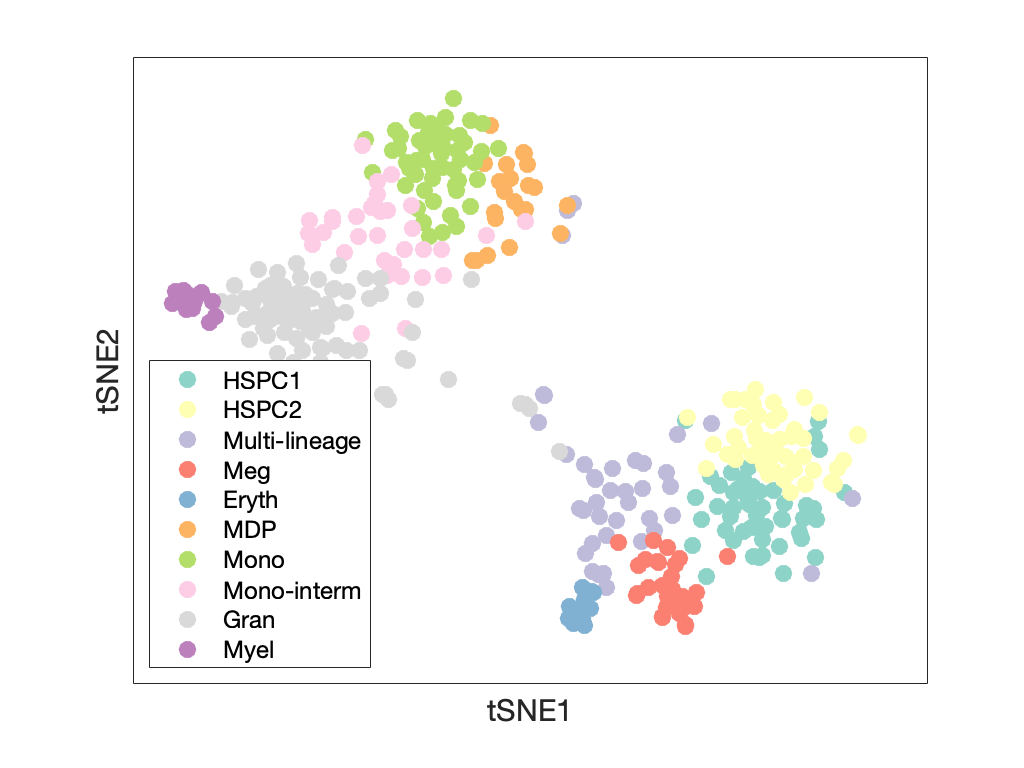

name_exp = {'HSPC1','HSPC2','Meg','Eryth','Multi-lin','MDP','Mono','Gran','Myel'};
name_cluster = {'HSPC1','HSPC2','Multi-lineage','Meg','Eryth','MDP','Mono','Mono-interm','Gran','Myel'};
colors_exp = brewermap(9,'paired');
colors_cluster = brewermap(k,'set3');
labs_perm = Output.labs_perm;


Output.embedding_2d = score_tsne(perm_class,:);
score_2d = score_tsne(perm_class,:);

figure;
gscatter(score_2d(:,1),score_2d(:,2),class_order,colors_cluster,[],30);
legend(name_cluster,'Fontsize',12,'Location','SouthWest')
set(gca,'xtick',[],'ytick',[]);
xlabel('tSNE1','Fontsize',15)
ylabel('tSNE2','Fontsize',15)

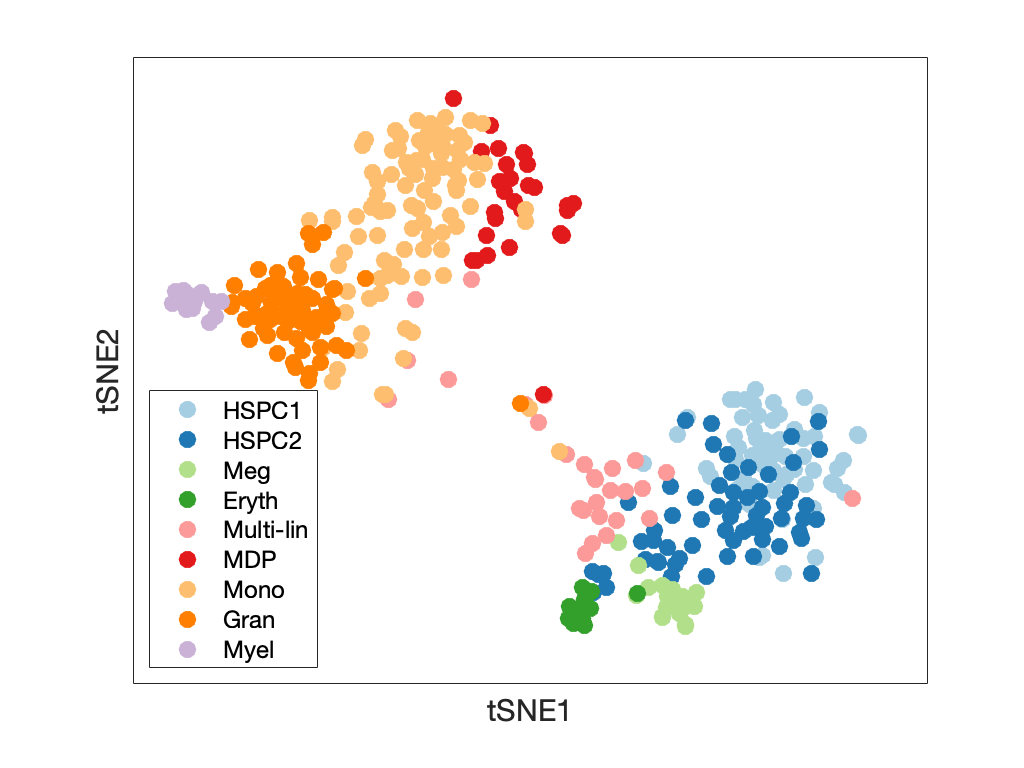

Output.embedding_2d = score_2d;

figure;
gscatter(score_2d(:,1),score_2d(:,2),labs_perm,colors_exp,[],30);
legend(name_exp,'Fontsize',12,'Location','SouthWest')
set(gca,'xtick',[],'ytick',[]);
xlabel('tSNE1','Fontsize',15)
ylabel('tSNE2','Fontsize',15)

Output.embedding_2d = score_2d;

Construct landscape

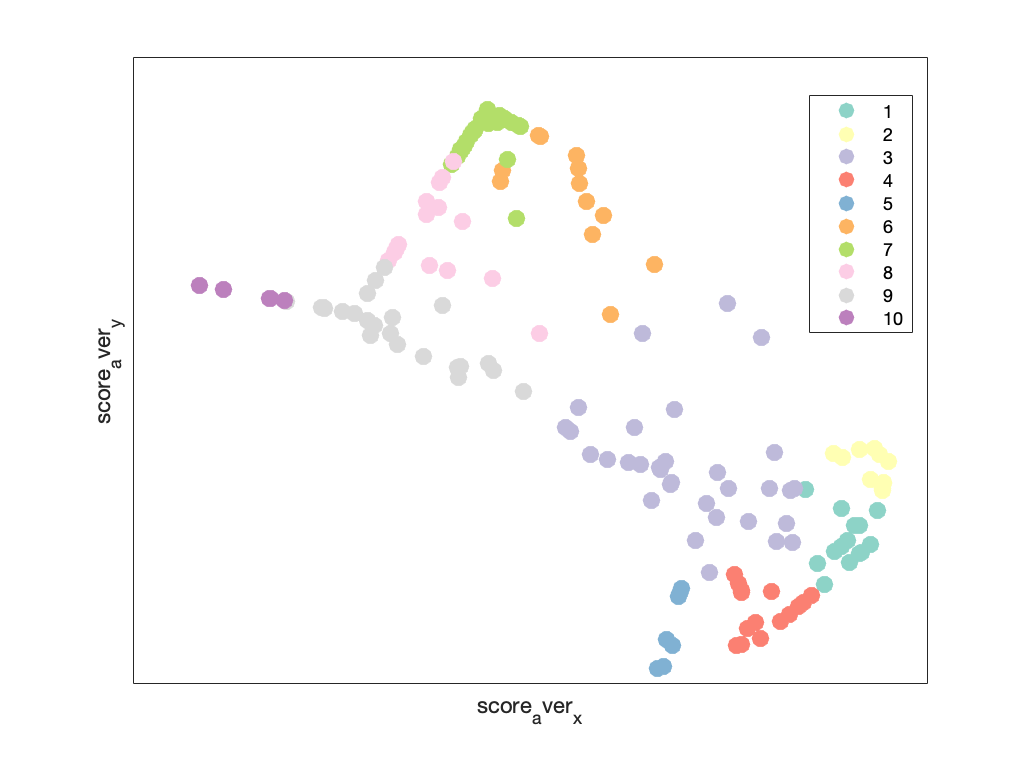


par.thresh_calc_center = 0.9;
par.thresh_calc_cov = 0.2;
par.N_mesh = 1000;
par.mksize = 30;
par.scaleaxis = 1.1; 
par.scalevalue = 1.1; 
par.fontsize = 30;
par.alpha = 0.4;

par.plot_label = class_order;
par.legend_text = name_cluster;
par.colors = colors_cluster;
par.color_mixing = true;

land = ConstructLandscape (Output, par);

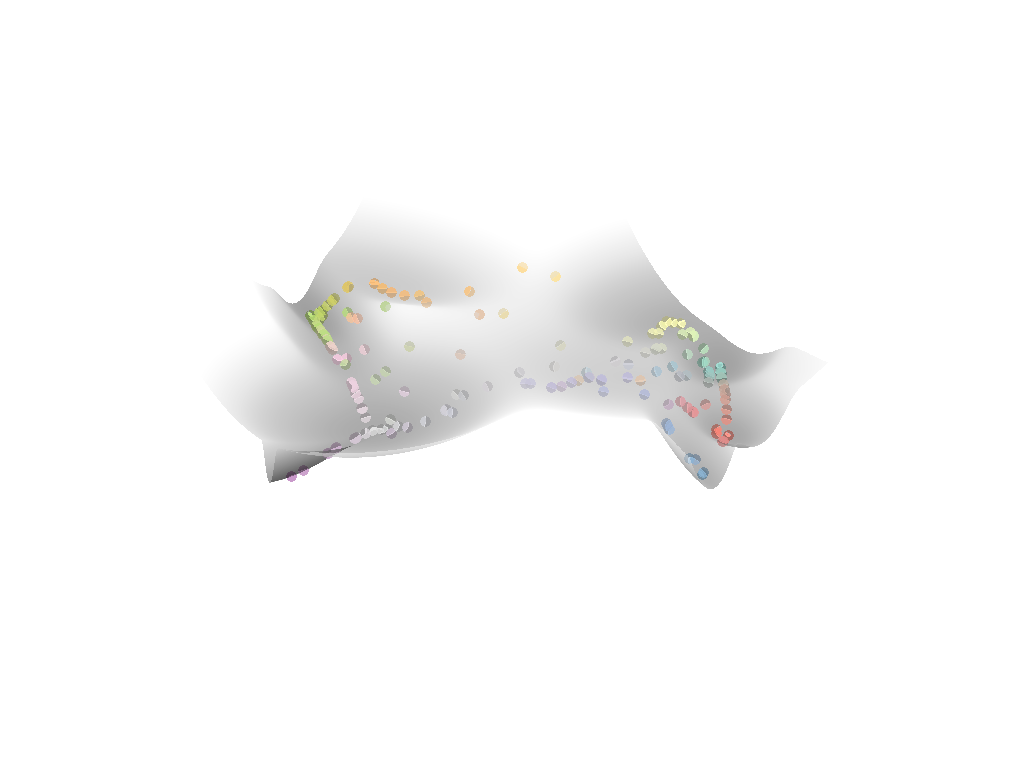

view([-46 81])

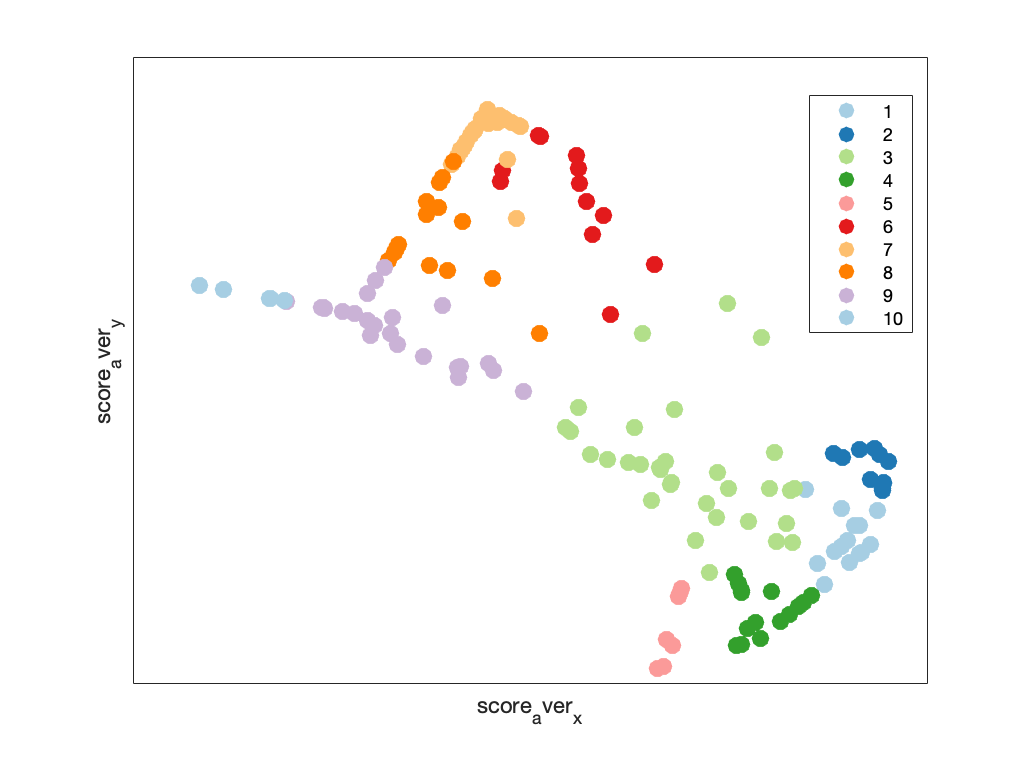


%colored by true label
par.color_mixing = false;
par.colors = colors_exp ;
par.legend_text = name_exp;
labs_perm = Output.labs_perm;
par.plot_label = labs_perm;
land = ConstructLandscape (Output, par);

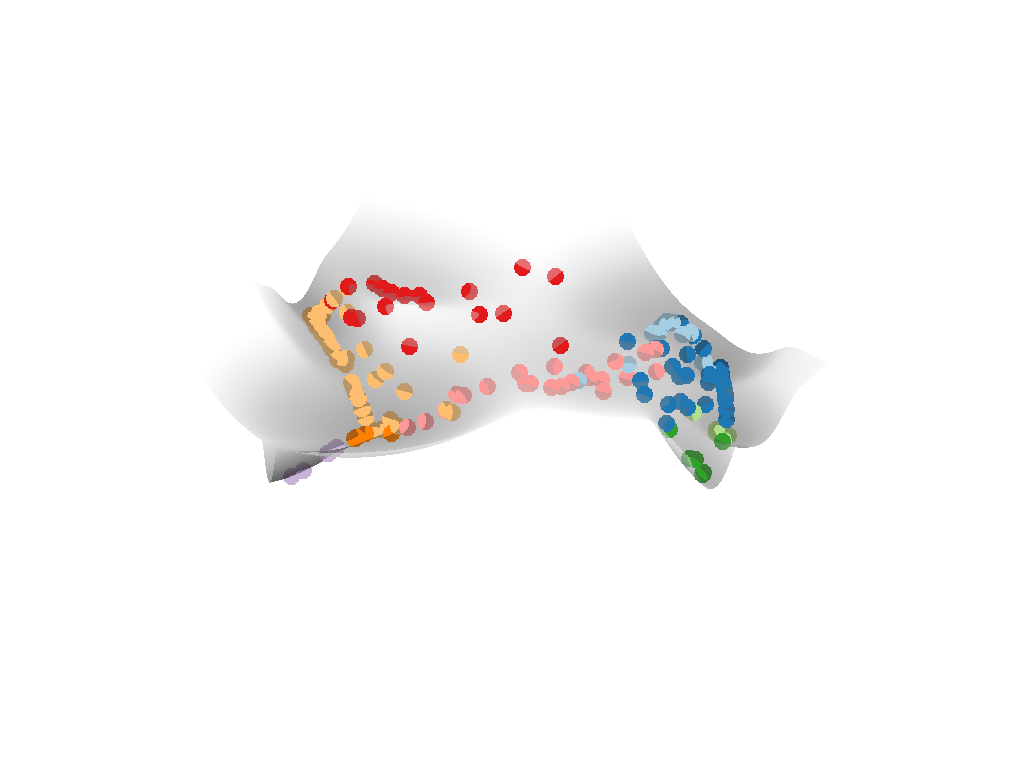

view([-46 81])

## Transcendental transigion cell and gene analysis

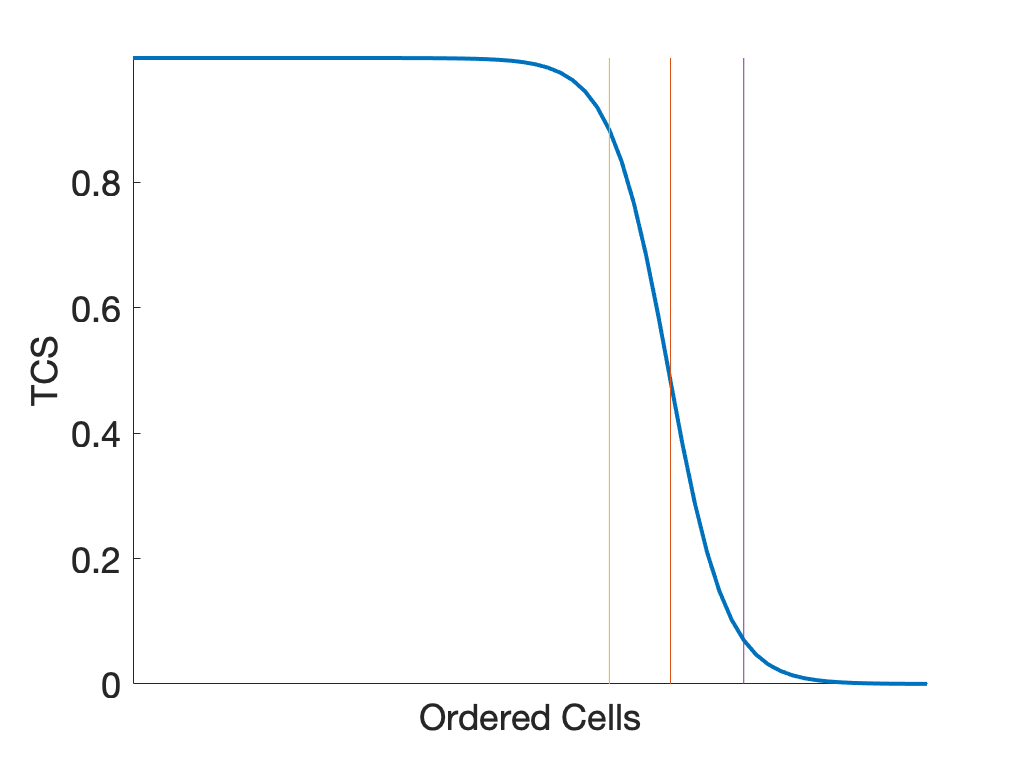

Below is the heatmap of transition genes


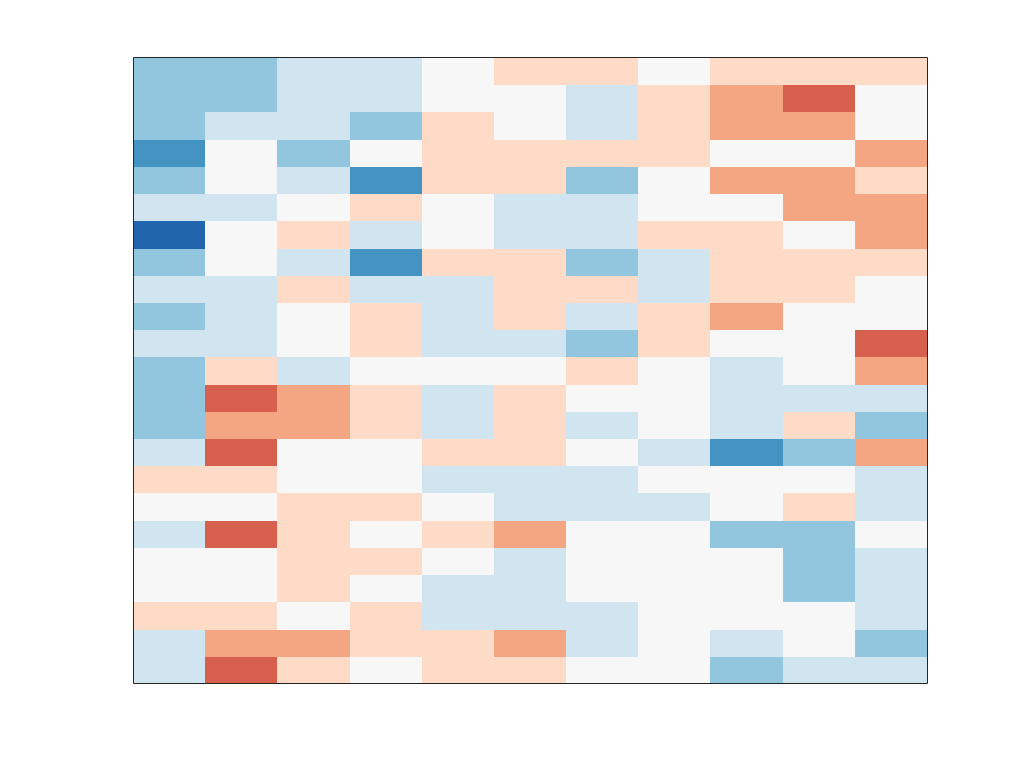

Below is the heatmap of down-regulated MS/IH genes

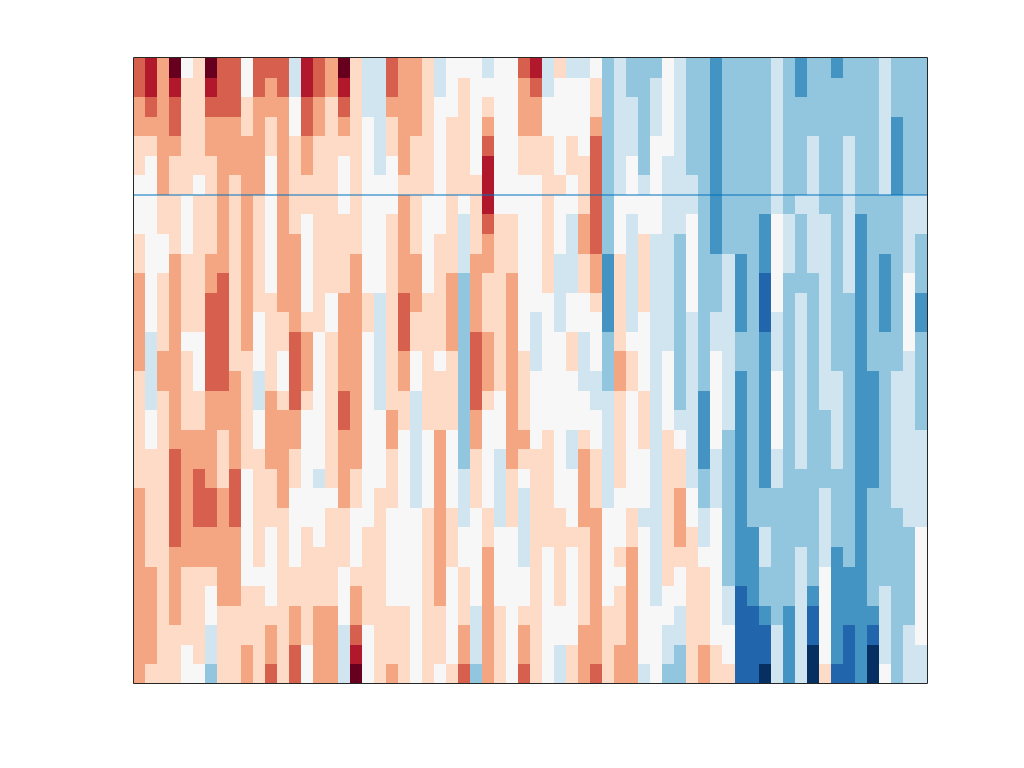

Below is the heatmap of up-regulated MS/IH genes


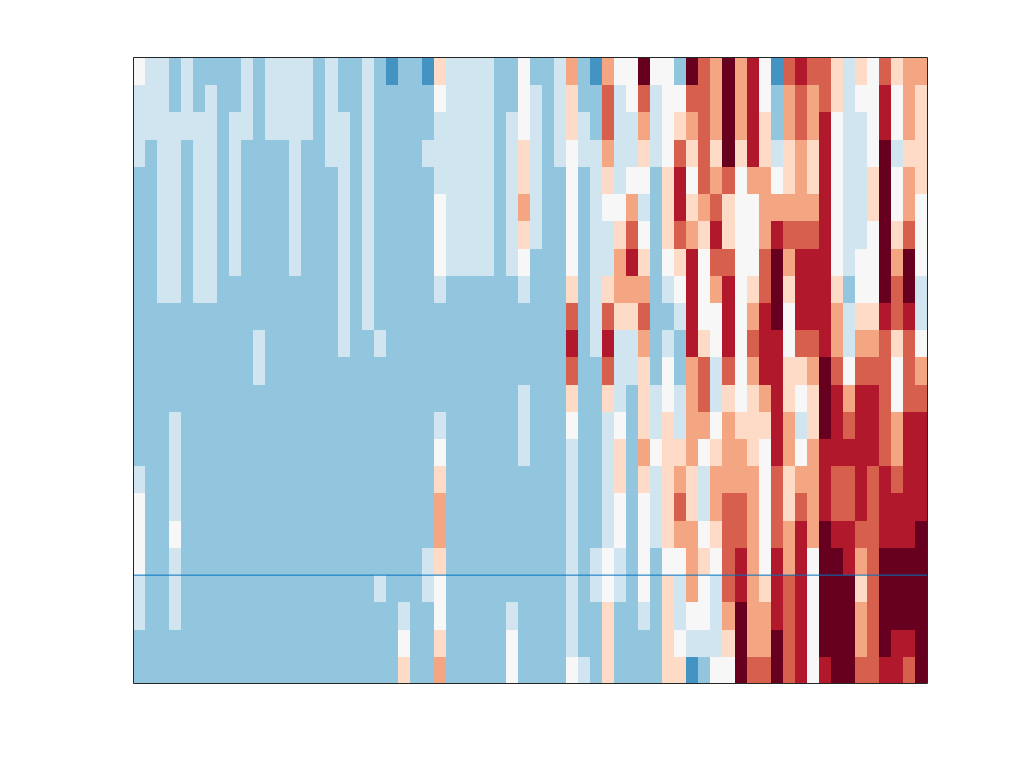

Below is the gradual cell indentity change of the interested process


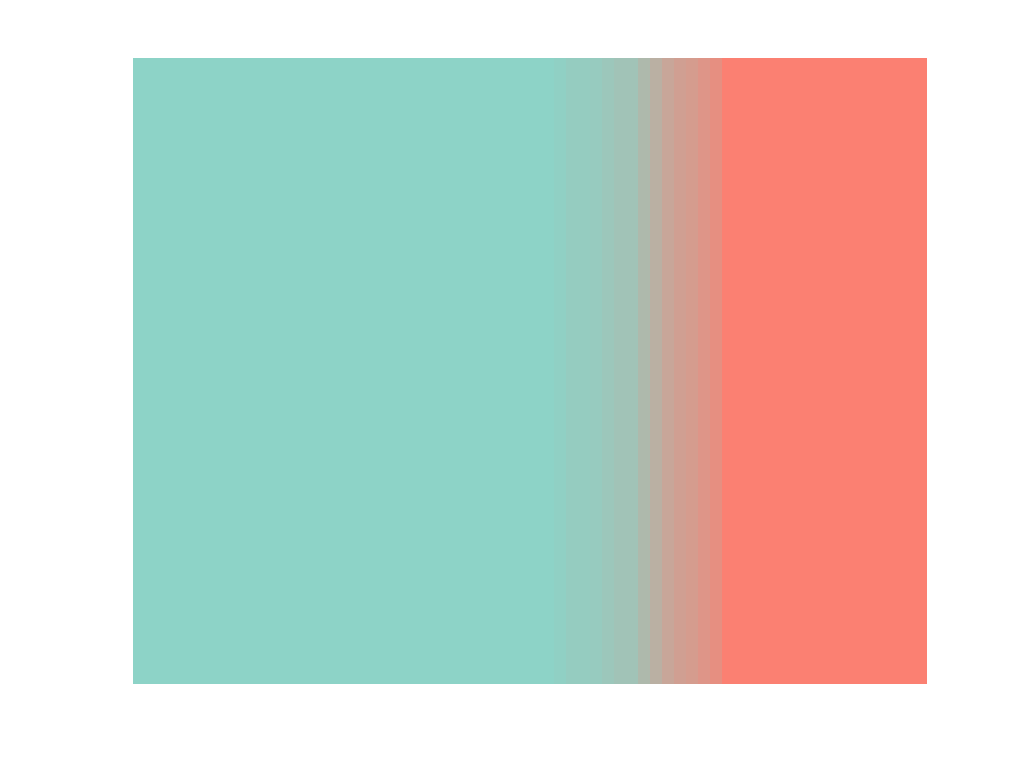

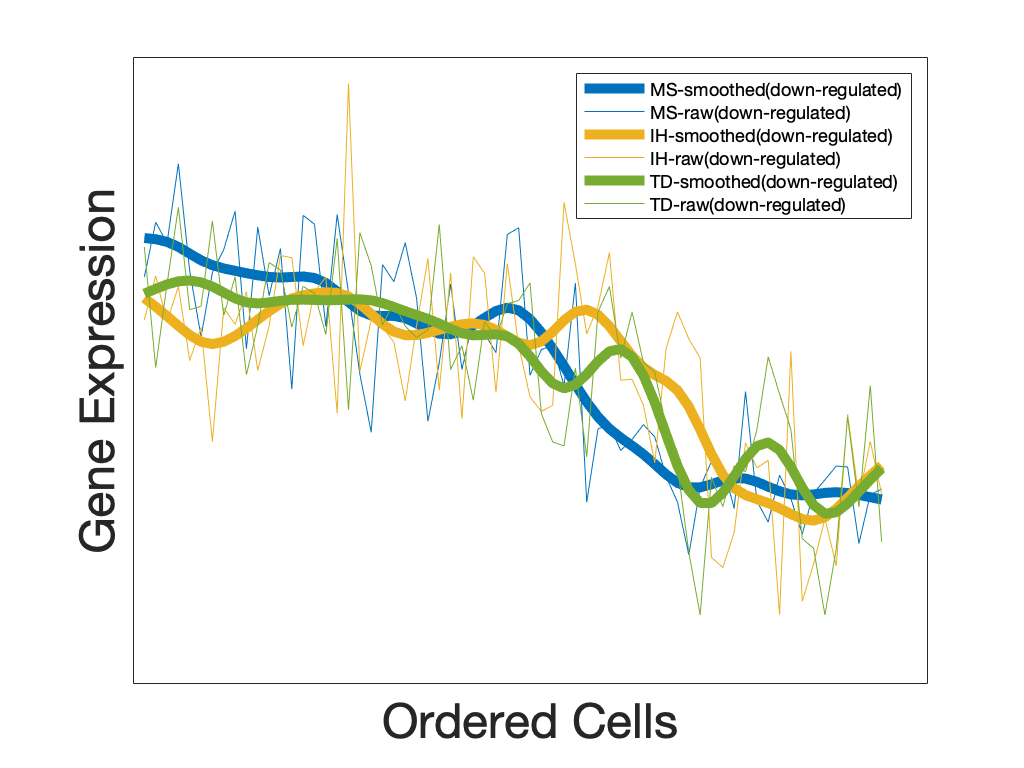

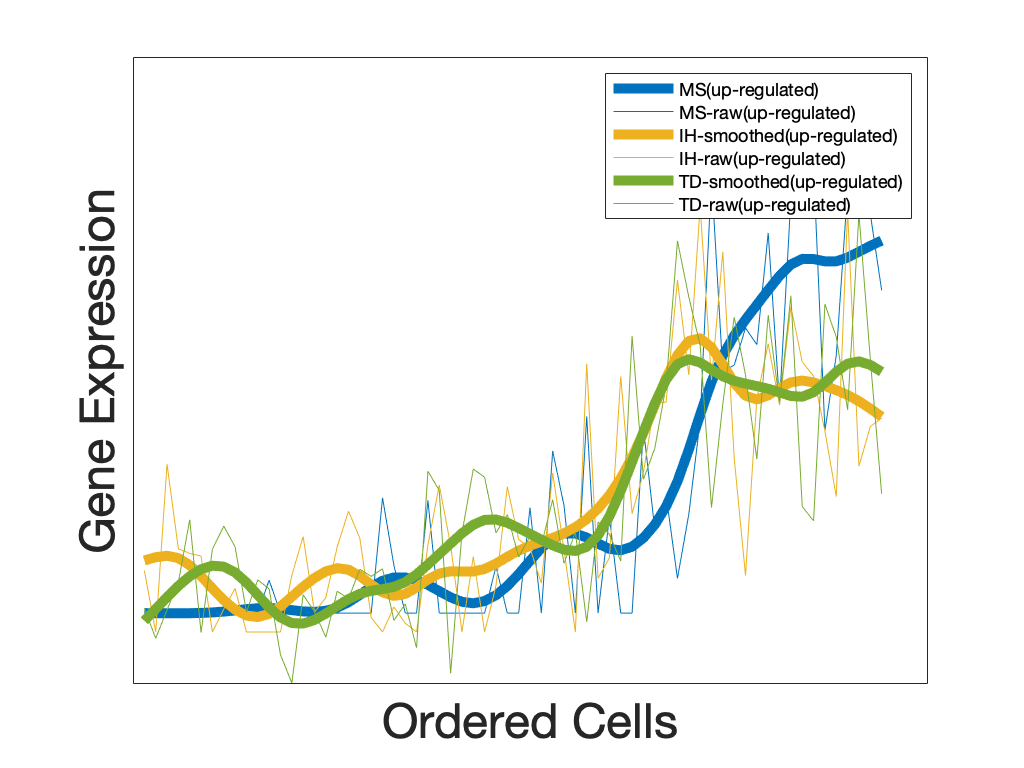

genes = gene_name_select;
par.genes = genes;
par.true_labs = labs_perm;
par.thresh_otherkeep = 0.2;
par.thresh_de_pvalues = 5e-3;
par.thresh_ms_pvalues = 1e-2;
par.thresh_tcs = 0.4;
par.thresh_td_genes = 0.4;
par.colors = colors_cluster ;

par.flip = false;
par.display_genes_label = false;

% check the state id before preceeding due to possible randomness of
% clustering id. Results unchanged.
out_14 = GeneAnalysis(1, 4, Output,par);

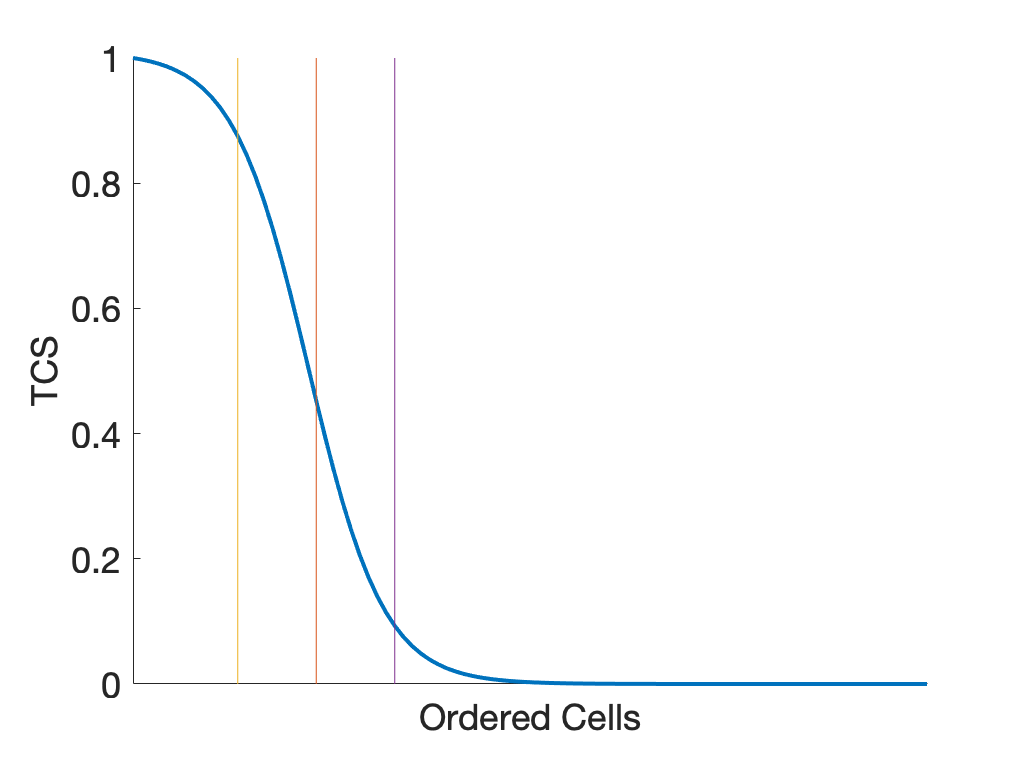

Below is the heatmap of transition genes


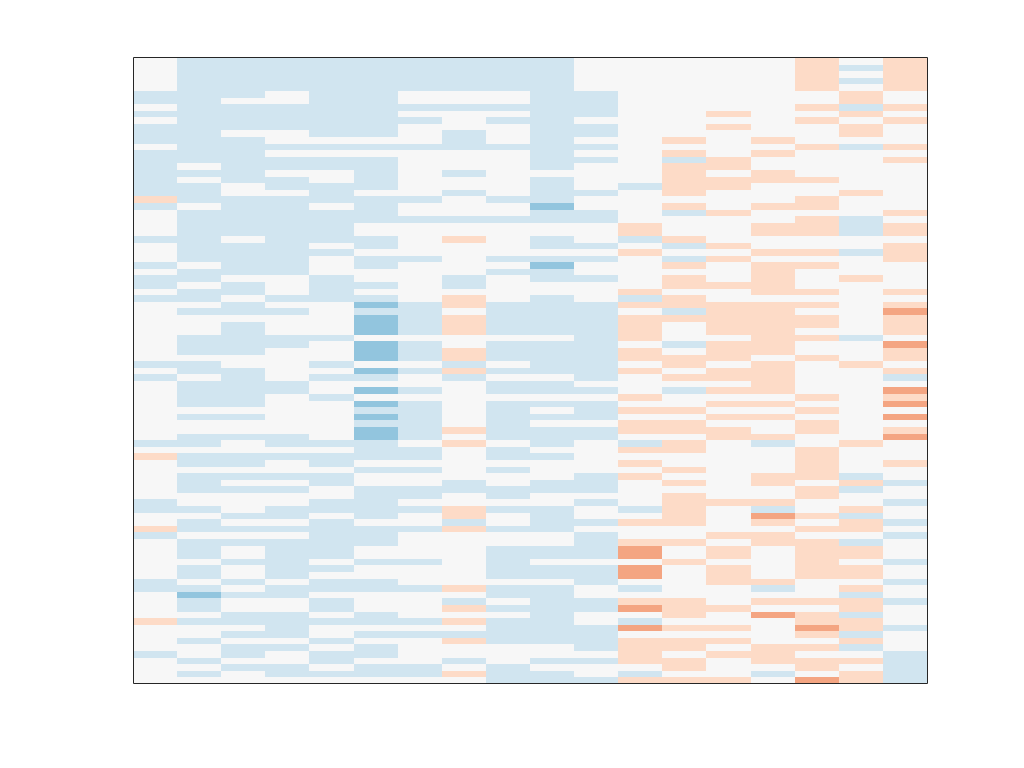

Below is the heatmap of down-regulated MS/IH genes


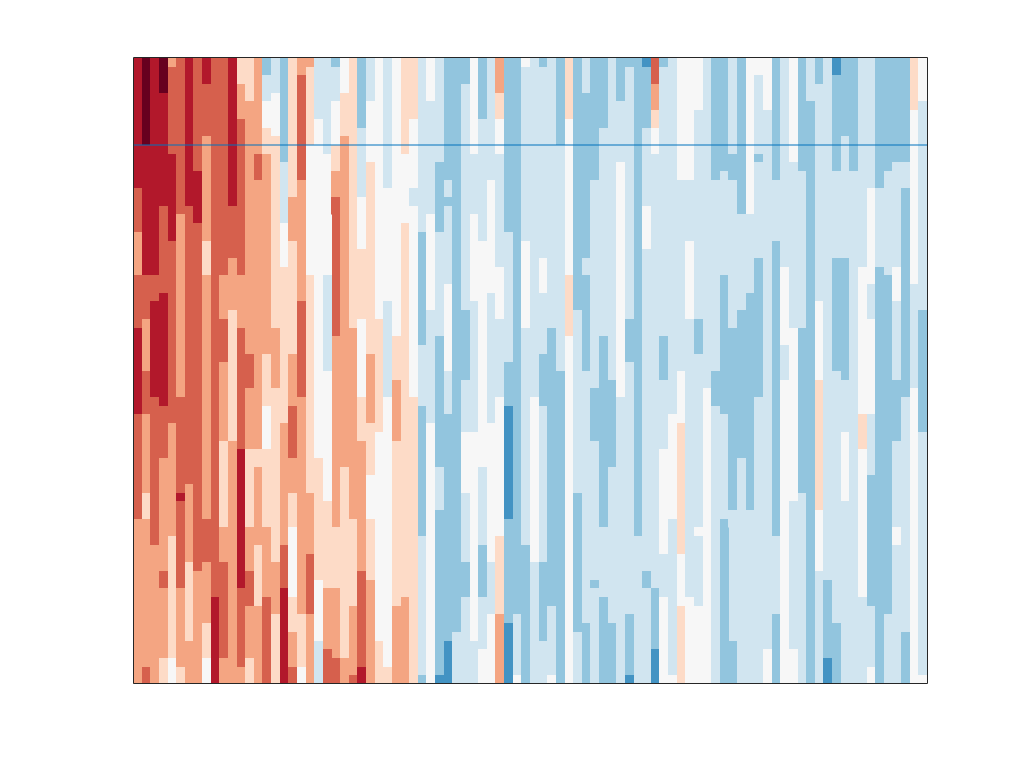

Below is the heatmap of up-regulated MS/IH genes


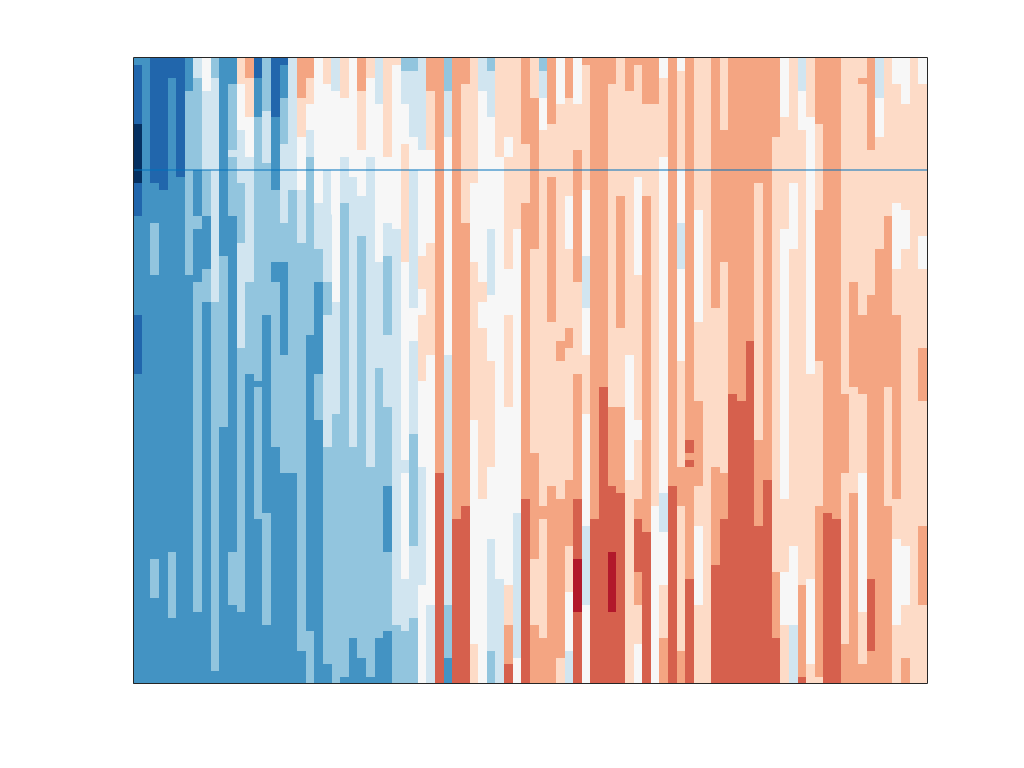

Below is the gradual cell indentity change of the interested process


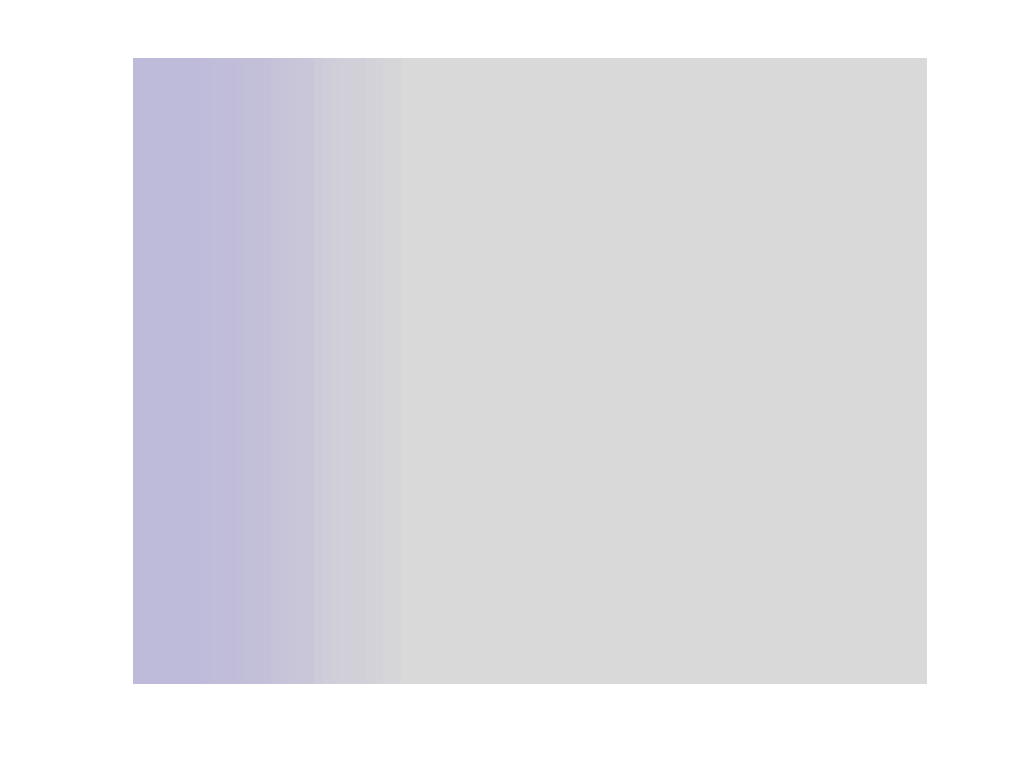

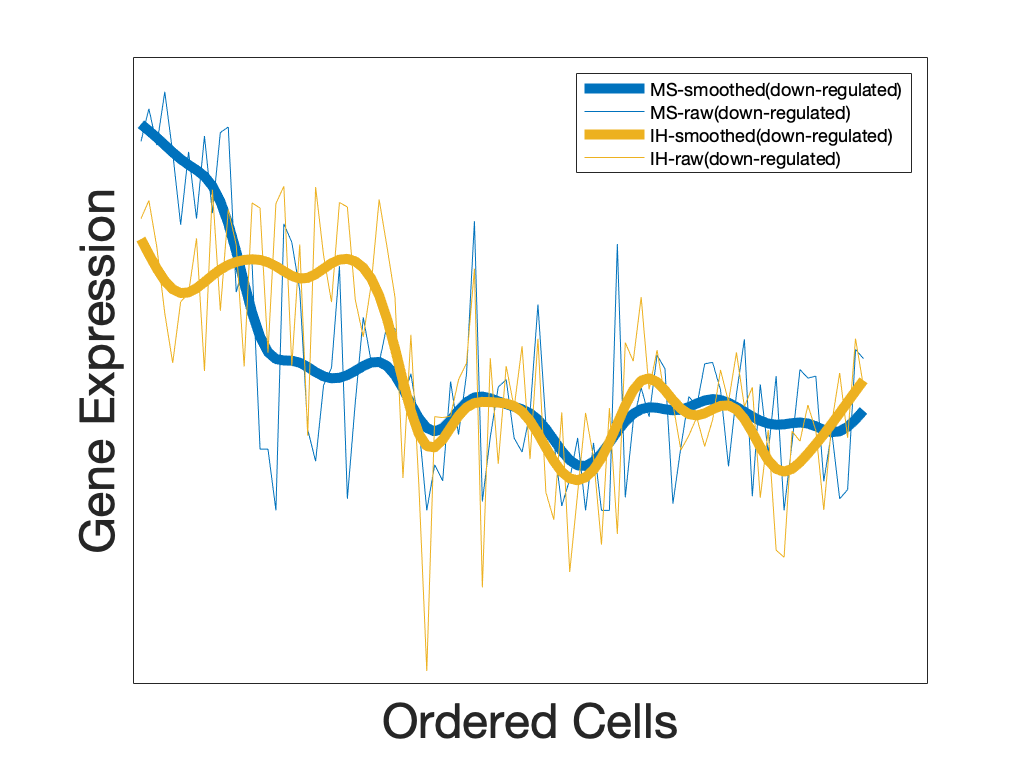

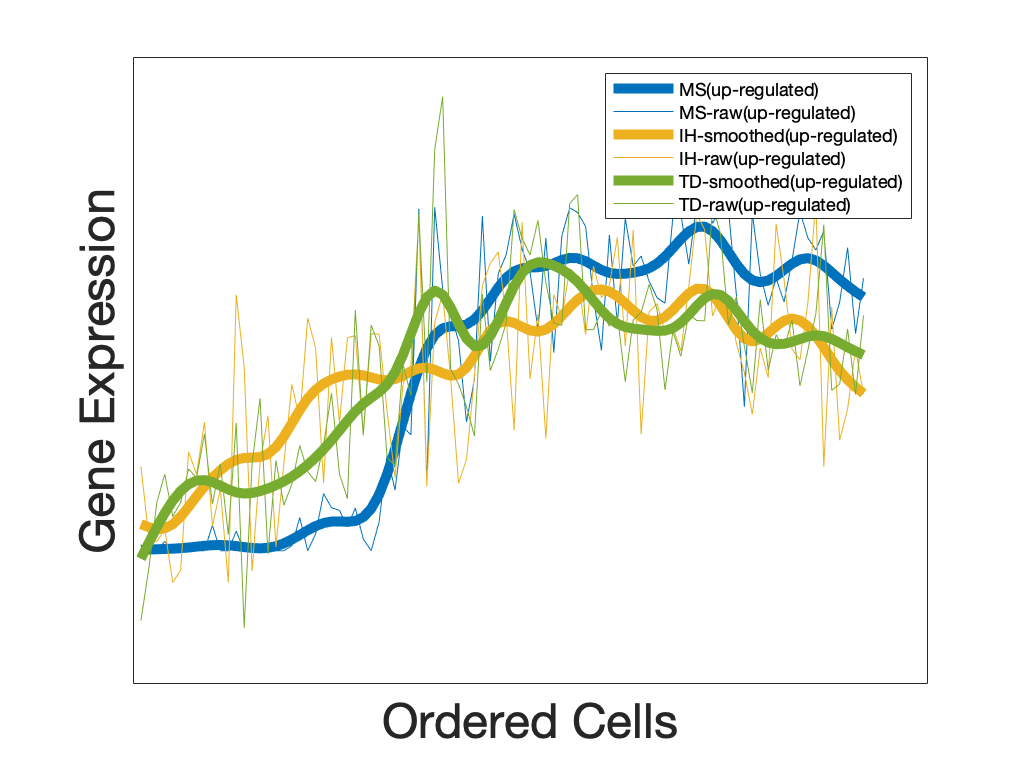


par.L_select_top_genes = 5;
out_39 = GeneAnalysis(3, 9, Output,par);

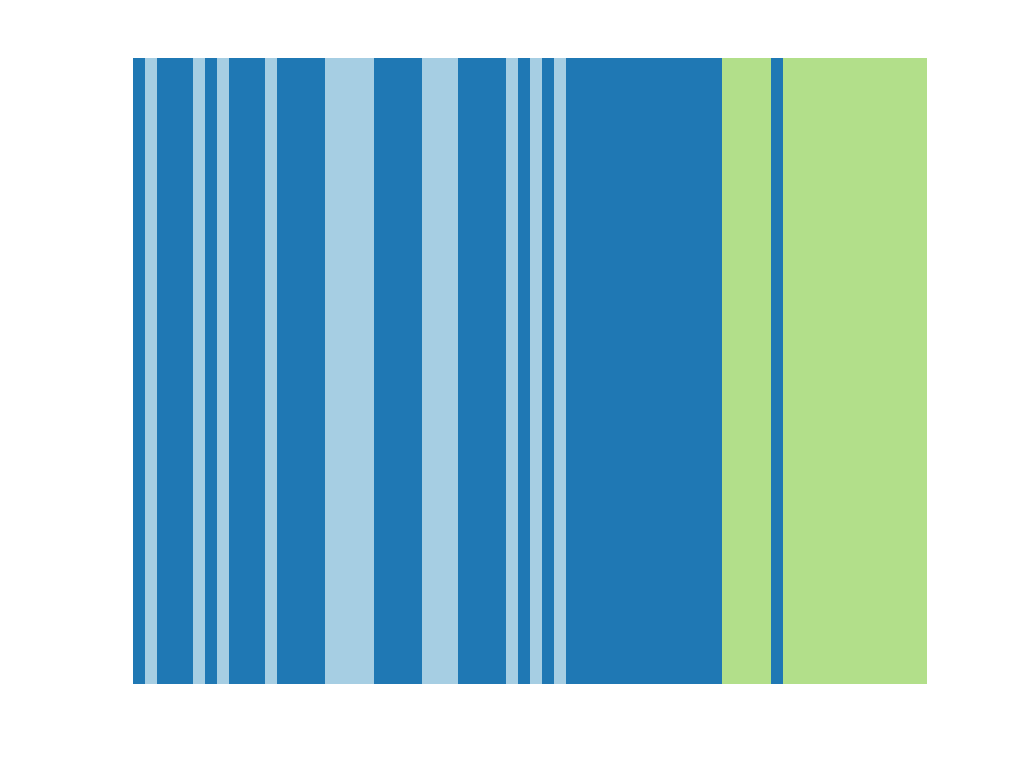


figure;
imagesc(out_14.cell_true_lab')
colormap(colors_exp)
caxis([1 10])
axis off
set(gca,'xtick',[],'ytick',[]);
box off

## output other data in Supplementary

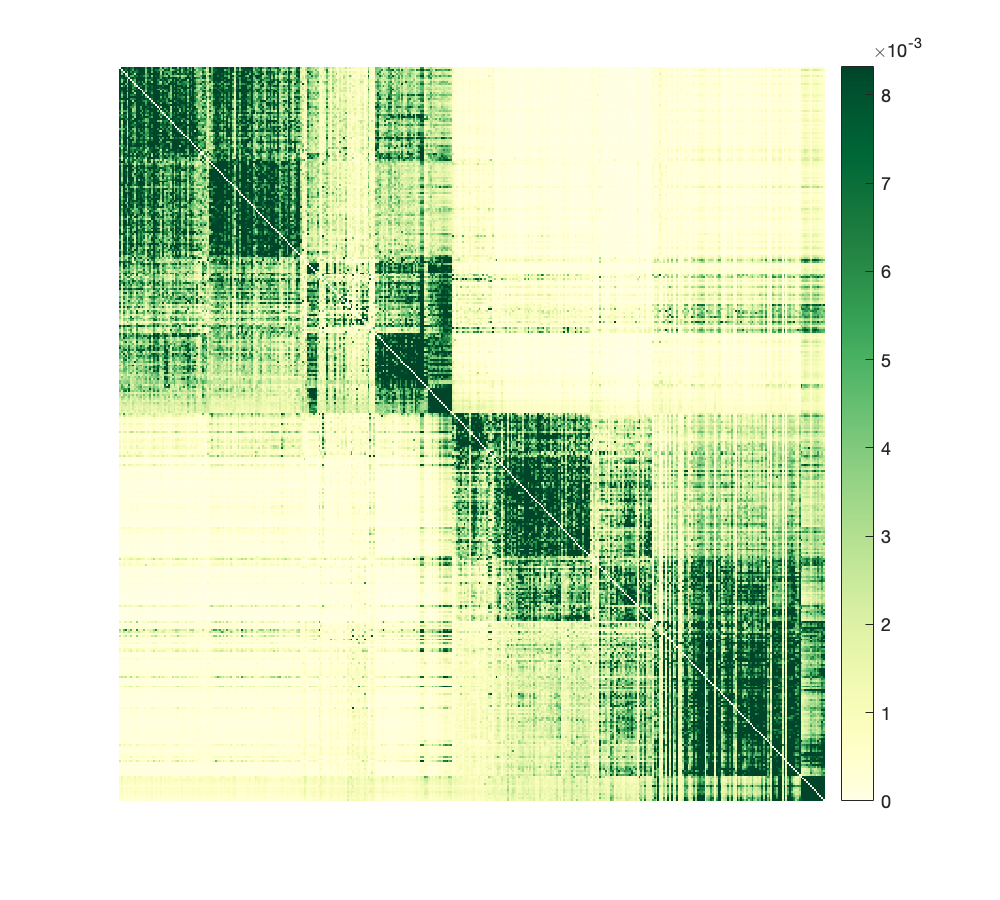

rho_class = Output.rho_class;
perm_class = Output.perm_class;
P_hat = Output.P_hat;
P_appr_perm = Output.P_appr_perm;
P_perm = Output.P_perm;
P_rho = Output.P_rho;
labs_perm = Output.labs_perm;
mu_hat = Output.mu_hat;
k = Output.k;
H = Output.H;


max_P = 0.2* max(max(P_rho));
c_lim = [0 max_P];
cmp = 'ylgn';

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
colorbar;

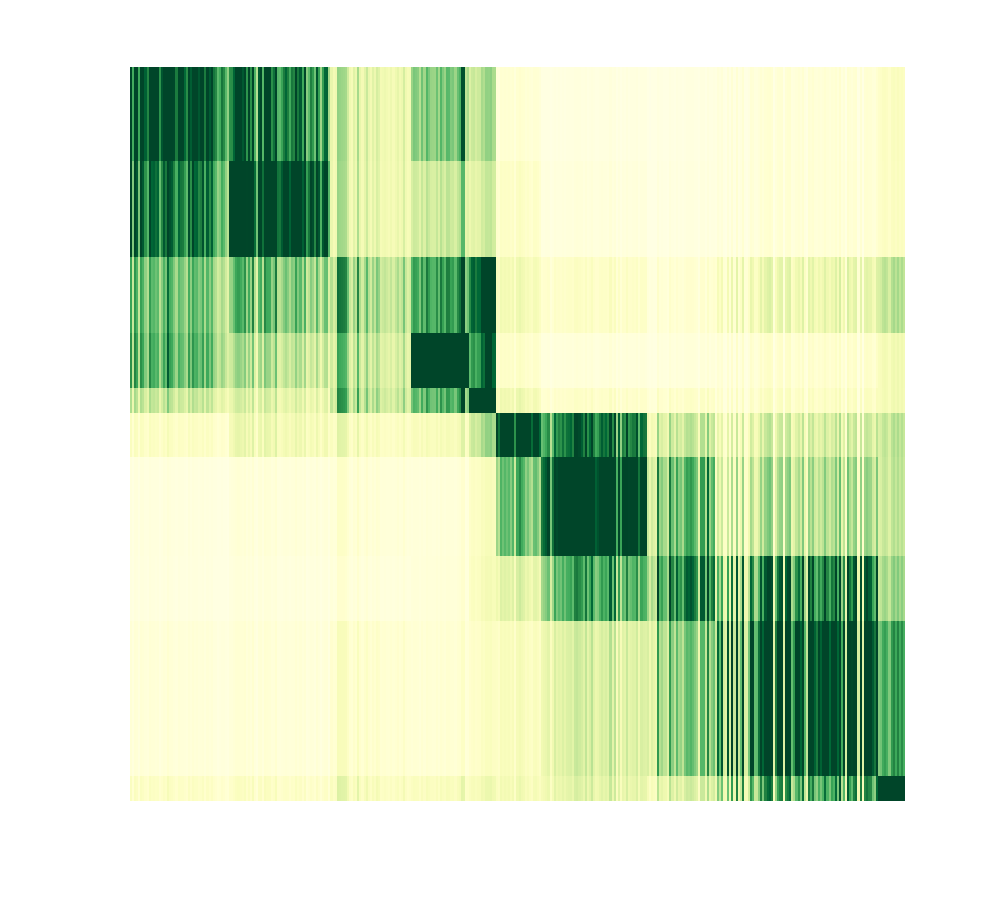



figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_appr_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

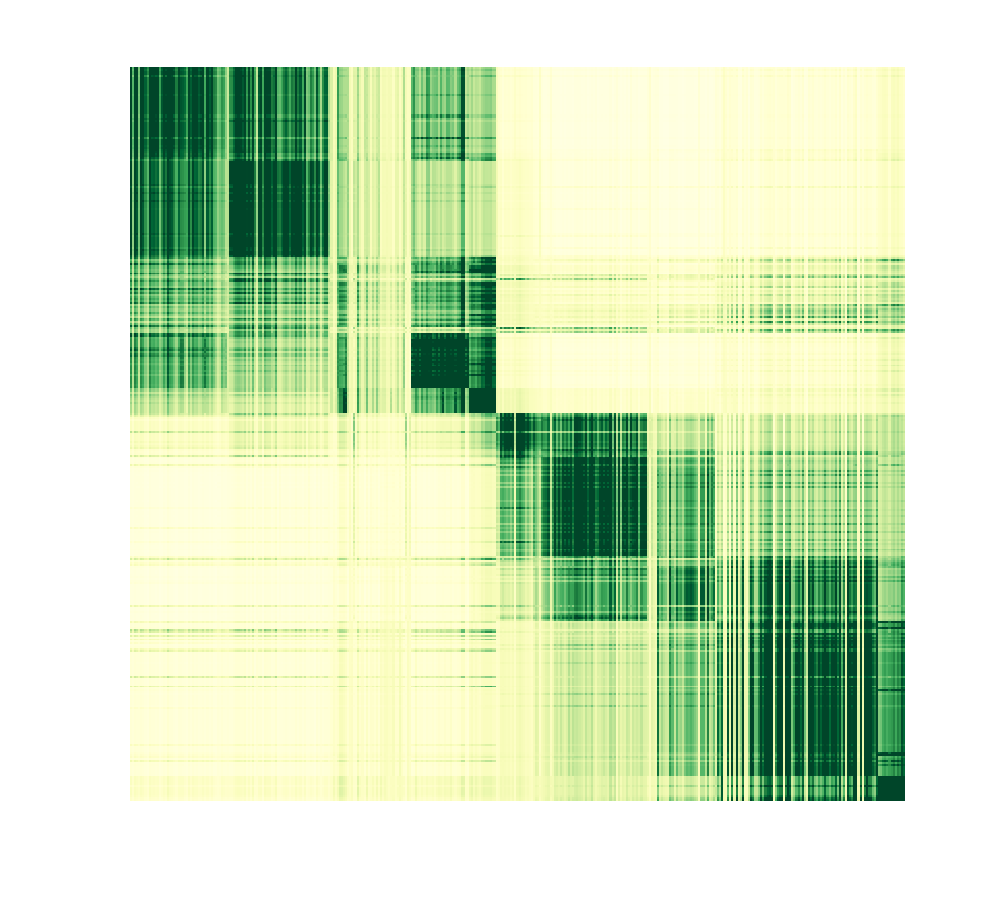

%colorbar;


figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_rho);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
%colorbar;
box off

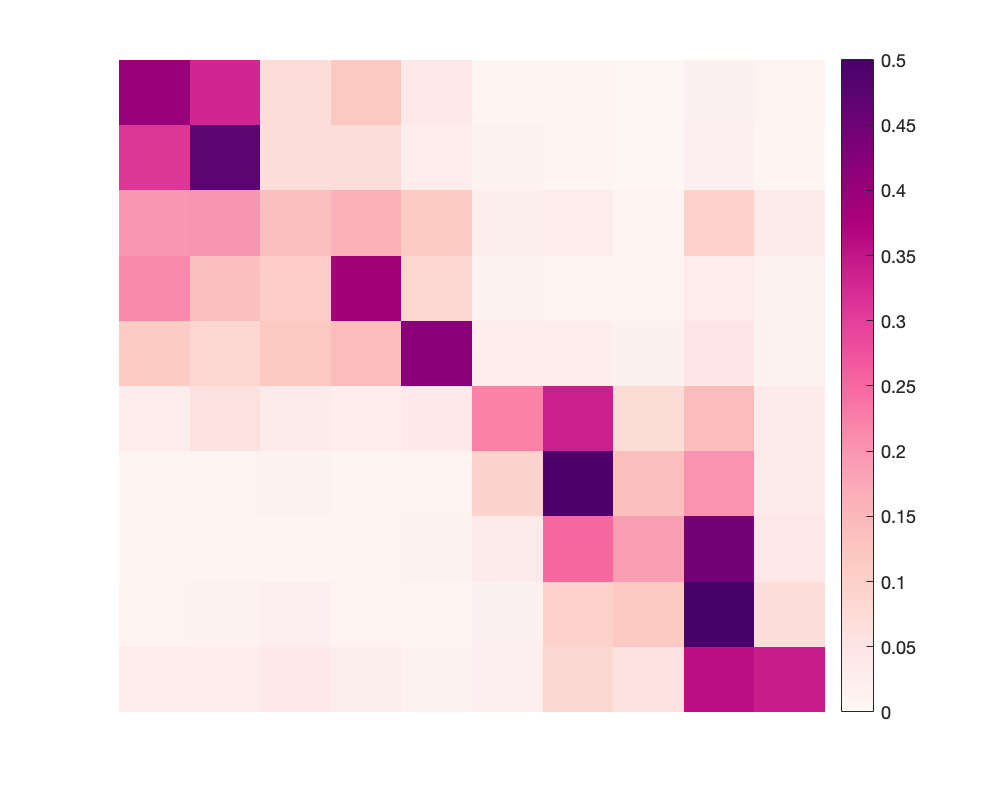



cmp = 'rdpu';
figure('rend','painters','pos',[10 10 500  400])
colormap(brewermap([],cmp))
imagesc(P_hat);
caxis([0 0.5])
axis off
set(gca,'xtick',[],'ytick',[]);
box off
colorbar;

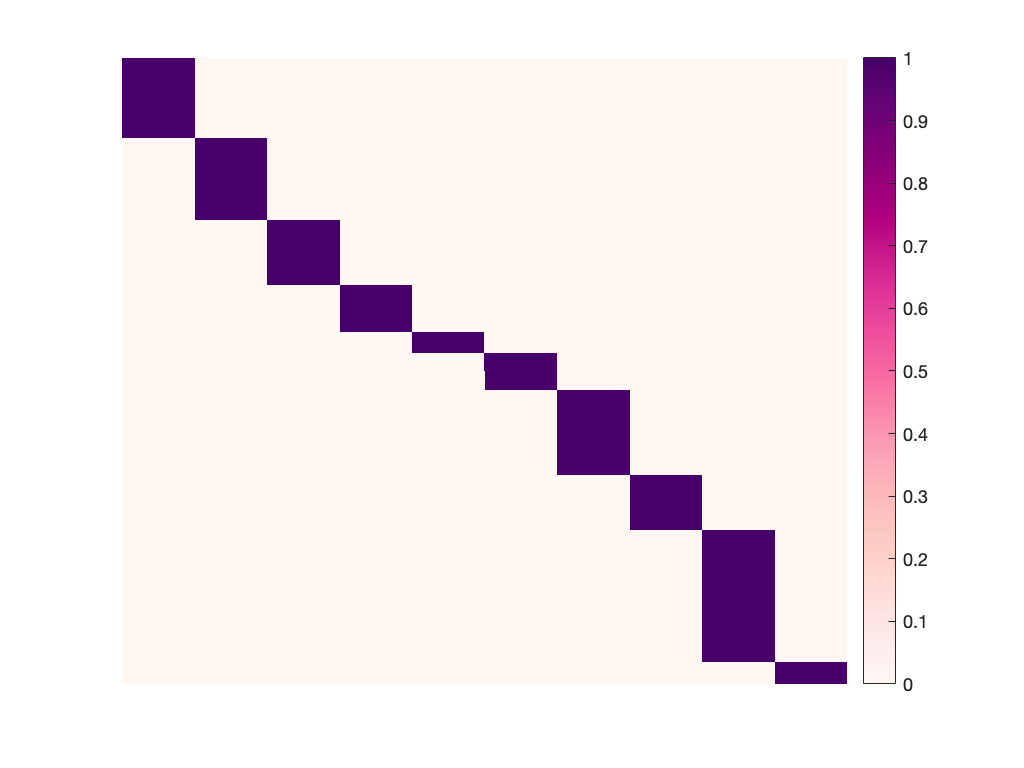


figure;
for id_cluster  = 1:k
member(:,id_cluster) = (class_order == id_cluster)';
end
colormap(brewermap([],cmp))
imagesc(member);
caxis([0 1])
colorbar;
axis off
set(gca,'xtick',[],'ytick',[]);
box off

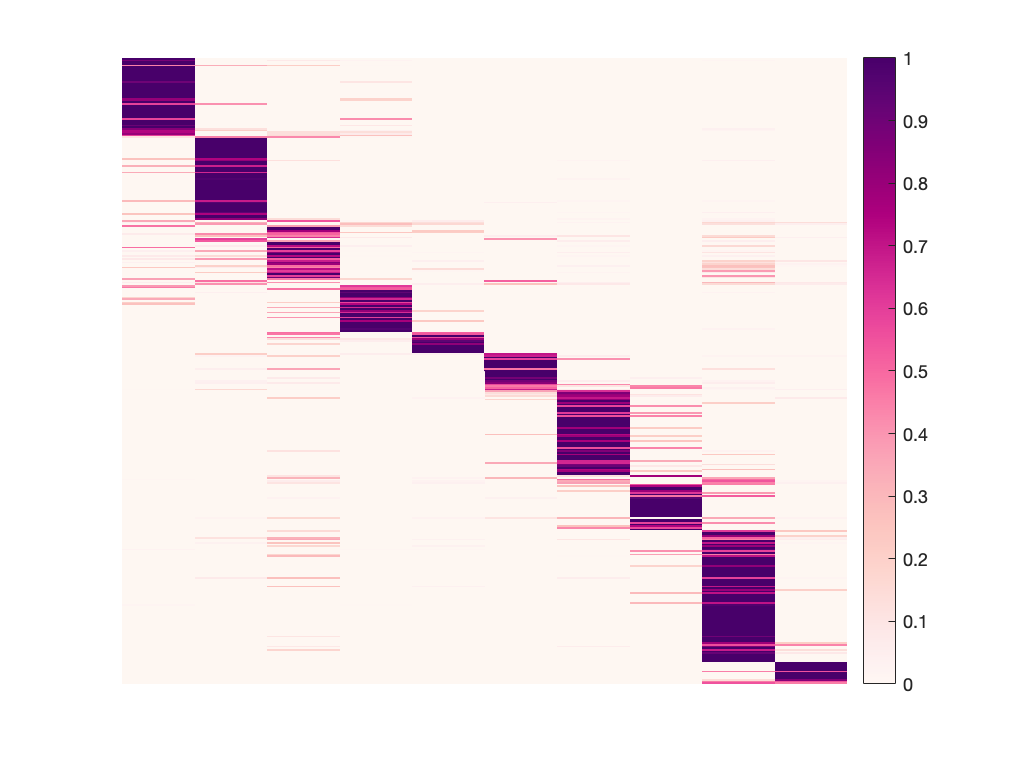


figure;
colormap(brewermap([],cmp))
imagesc(rho_class);
caxis([0 1])
colorbar;
axis off
set(gca,'xtick',[],'ytick',[]);
box off